GAAAUSIAAN

`  training: [nlZ dnlZ] = gp(hyp, inf, mean, cov, lik, x, y);` `nlZ` is the negative log marginal likelihood and `dnlZ` its partial derivatives wrt the hyperparameters (which are used for training the hyperparameters). 

` prediction: [ymu ys2 fmu fs2 lp] = gp(hyp, inf, mean, cov, lik, x, y, xs, ys); t`he prediction outputs are `ymu` and `ys2` for test output mean and covariance, and `fmu` and `fs2` are the equivalent quanteties for the corresponding latent variables. Finally, `lp` are the test output log probabilities

`Keep the 10% secret (X, Y), and only use this at the very end when we know what we are testing for (its a seecret) USE X/YT`

`Either use CV for tunning into different length scales per kernel + mean function? `

`or if different approach you can still do another 10% partition test`

% make sure to add to environment the gp_mit package with SUBfolders
data = readtable('data_reduced.csv')

data = 328×47 table
    Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    matrixSTRENGTH    matrixStrainbreak    matrixImpact    impurityE    impuritySTRENGTH    impurityStrainbreak    impurityImpact    matrixXc    impurityXc    blendE    blendSTRENGTH    blendStrainbreak    blendImpact    MajorityPolymer_H

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

afetr preprocessing  (in XE ) there are only 5 vars non-discrete, and one is the percentage of mixture so that is already scaled to range between 0-1, 

14-17  will then just be divided by thir respective maxs and adjust to the scale. 

% skipping  Strenth Impact Strain Break
E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  


% normalize to range 0-1 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max (E(:,18)); 
cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17)); 
Xe(:,14:17)= cols_continuous_norm;
% what about encoded vars?!!
% means = mean(Xe); Xe = Xe - means 

## keep 10% and stratify yE in 5 bins 

THIS test  set is not used until the very end to asses how they all do equally, SECRET

*repeatng : `Keep the 10% secret (X, Y), and only use this at the very end when we know what we are testing for (its a seecret) USE X/YT`

`Either use CV for tunning into different length scales per kernel + mean function? `

`or if different approach you can still do another 10% partition test`

%creating 5 bins 
binEdgesI = linspace(min(Ye), max(Ye), 6)

binEdgesI =     0.0302    0.2242    0.4181    0.6121    0.8060    1.0000


% Get the bin indices for each instance
binIndicesI = discretize(Ye, binEdgesI)

binIndicesI =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Split the data into a training set and test set with stratification
cvI = cvpartition(binIndicesI, 'Holdout', 0.1)

cvI = Hold-out cross validation partition
   NumObservations: 328
       NumTestSets: 1
         TrainSize: 296
          TestSize: 32

%boolean vectors
trainingIndicesI = training(cvI);
secretIndices = test(cvI);

XT = Xe(trainingIndicesI,:);
Xsecret = Xe(secretIndices, :);
YT = Ye(trainingIndicesI);
Ysecret = Ye(secretIndices);

### HOLDOUT method validation 10% set (10%secretTEst,

% fast splitting for training and validation set 
 [r, c ]=size(XT)

r = 296

c = 29

 PD = 0.90 ;
 idx = randperm(r);
 Xtrain = XT(idx(1:round(r*PD)),:);
 XVal = XT(idx(round(r*PD)+1:end),:);

Ytrain = YT(idx(1:round(r*PD)),:);
YVal = YT(idx(round(r*PD)+1:end),:);

### CV : (val +train)90% for 10-k fold  (10%secret,

redo binIndices with the training set, as binIndices

binEdgesT = linspace(min(YT), max(YT), 6)

binEdgesT =     0.0314    0.2251    0.4188    0.6125    0.8063    1.0000


binIndicesT = discretize(YT, binEdgesT)

binIndicesT =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


cv        = cvpartition(binIndicesT,'kfold',10);
numtestsets   = cv.NumTestSets;

#### Trying simple regression 1D 

practice so holdout method

%Trying simple regression 1D 
x = Xtrain(:,14);
xs = XVal(:,14)

xs =     0.0601
    0.0516
    0.0516
    1.0000
    0.7297
    0.5223
    0.9631
    0.7297
    0.2976
    0.2789


y = Ytrain;
ys = YVal;

%HYPermeter : [mean, cov, lik] and GP(hyp, inference, name_functions m, c,
%l, x, y, and if test ) HYP should agree with specific NAME

meanfunc = [];    covfunc = @covSEiso;   likfunc = @likGauss; 
hyp = struct('mean', [] , 'cov', [0 0], 'lik', log(0.1));
nlml = gp(hyp, @infGaussLik, meanfunc , covfunc, likfunc, x, y)

nlml = -192.9760


%  gp returns the mean m variance s2 at the test location (each)
%s2 to shown the confidence interval bound 
[m, s2] = gp(hyp,@infGaussLik, meanfunc, covfunc, likfunc, x, y, xs)

m =     0.1140
    0.1071
    0.1071
    0.8548
    0.6715
    0.5049
    0.8327
    0.6715
    0.3134
    0.2974


s2 =     0.0101
    0.0101
    0.0101
    0.0103
    0.0101
    0.0101
    0.0102
    0.0101
    0.0101
    0.0101



 n = size(m,1); mape_training =  calculateMAPE(ys,m,  n)

mape_training = 32.1819


hyp1 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value -1.929760e+02
Function evaluation      4;  Value -1.962896e+02
Function evaluation      7;  Value -1.976488e+02
Function evaluation     11;  Value -1.976495e+02
Function evaluation     16;  Value -1.976988e+02
Function evaluation     19;  Value -1.977000e+02
Function evaluation     22;  Value -1.977081e+02
Function evaluation     25;  Value -1.977081e+02
Function evaluation     28;  Value -1.977081e+02
Function evaluation     31;  Value -1.977081e+02
Function evaluation     34;  Value -1.977081e+02
Function evaluation     37;  Value -1.977081e+02
Function evaluation     40;  Value -1.977081e+02
Function evaluation     43;  Value -1.977081e+02
Function evaluation     46;  Value -1.977081e+02
Function evaluation     49;  Value -1.977081e+02
Function evaluation     53;  Value -1.977081e+02
Function evaluation     56;  Value -1.977081e+02
Function evaluation     60;  Value -1.977081e+02
Function evaluation     64;  Value -1.977081e+02
Function evaluation 

infered_noise_st= exp(hyp1.lik)

infered_noise_st = 0.1112

nlml1 = gp(hyp1, @infGaussLik, meanfunc, covfunc, likfunc, x, y)

nlml1 = -197.7081

 %exp(nlml2 -nlml) = ratio decrease of joint probality (density) of training
%data
dec_jp = exp(nlml1 -nlml) 

dec_jp = 0.0088

%mape_values_1D= zeros(10,1)
 %for i=1 : 10
   hyp2 = minimize(hyp1, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value -1.977081e+02


   [ymu1D, ys21D,fmu1D, fs21D, lp1D] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys)

ymu1D =     0.1145
    0.1073
    0.1073
    0.8582
    0.6678
    0.5041
    0.8341
    0.6678
    0.3165
    0.3006


ys21D =     0.0125
    0.0125
    0.0125
    0.0127
    0.0125
    0.0125
    0.0126
    0.0125
    0.0124
    0.0124


fmu1D =     0.1145
    0.1073
    0.1073
    0.8582
    0.6678
    0.5041
    0.8341
    0.6678
    0.3165
    0.3006


fs21D = 1.0e-03 *

    0.1419
    0.1499
    0.1499
    0.3137
    0.0912
    0.0953
    0.2454
    0.0912
    0.0837
    0.0824


lp1D =     1.1757
    1.2688
    1.0142
    0.5232
    1.1871
    1.0809
    1.2401
    0.8879
    1.1749
    1.2652


     n = size(ymu1D, 1); mape_1D = calculateMAPE(ys,ymu1D, n )

mape_1D = 32.3772

 %end
%mape_1D = mean(mape_values_1D)


ci =[ymu1D+2*sqrt(ys21D), ymu1D-2*sqrt(ys21D)]; corr1D = corr(ymu1D, ys )

corr1D = 0.9080

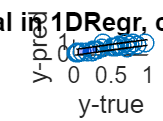

figure;
scatter(ys, ymu1D)
hold on;
patch([xs; flip(xs)], [ci(:,1); flip(ci(:,2))], 'b', 'FaceAlpha', 0.3);
xlabel('y-true');
ylabel('y-pred');
title(['95% Confidence Interval in 1DRegr, correlation between: ' num2str(corr1D)] );
hold off;

covfunc = @covSEiso; hyp.cov= [0; 0]

hyp = struct with fields:
    mean: 0.5000
     cov: [2×1 double]
     lik: -2.3026


likfunc = @likGauss; sn = 0.1; hyp.lik = log(sn);

meanfunc = {@meanSum, {@meanLinear, @meanConst}}; hyp.mean = [0.5; 1];
 %NN does not work!
 %meanfunc= @meanNN ; 
% meanfunc = []; hyp.mean =[];
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value -1.930871e+02
Function evaluation      4;  Value -1.963815e+02
Function evaluation      8;  Value -1.986907e+02
Function evaluation     13;  Value -1.997063e+02
Function evaluation     16;  Value -2.001855e+02
Function evaluation     17;  Value -2.005702e+02
Function evaluation     19;  Value -2.007287e+02
Function evaluation     21;  Value -2.007561e+02
Function evaluation     25;  Value -2.012329e+02
Function evaluation     27;  Value -2.015677e+02
Function evaluation     29;  Value -2.018104e+02
Function evaluation     31;  Value -2.019693e+02
Function evaluation     33;  Value -2.020400e+02
Function evaluation     35;  Value -2.021524e+02
Function evaluation     37;  Value -2.022023e+02
Function evaluation     39;  Value -2.022602e+02
Function evaluation     41;  Value -2.023644e+02
Function evaluation     43;  Value -2.024089e+02
Function evaluation     45;  Value -2.025410e+02
Function evaluation     47;  Value -2.027455e+02
Function evaluation 


[ymu, ys2,fmu, fs2, lp] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys);
n = size(ymu, 1) ; mape1D_means =  calculateMAPE(ys, ymu,  n)

mape1D_means = 35.6373


% cannot make mean discrete to work either.. 
% meanfunc= @meanDiscrete; hyp.mean = mean(x);
% hypD = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Error using meanDiscrete
s must be specified.

Error in gp (line 105)
if eval(feval(mean{:})) ~= numel(hyp.mean)

Error in minimize (line 77)
[f0 df0] = feval(f, X, varargin{:});          % get function value and gradient

% [ymuD, ys2D,fmu, fs2, lp] = gp(hypD, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs, ys);
% n = size(ymu, 1) ; mape1D_meanD =  calculateMAPE(ys, ymuD,  n)
 %"   hyp = [
%         mu_2
%         ..
%         mu_s ]

By changing the mean function to a sum of linear and constant, almost no improvement was clear 

### 2D prediction, still basic config

% starting with a 2d gp 
Xt2 = XT(:,13:14)

Xt2 =     0.5000    0.0601
    0.2000    0.0601
    0.1000    0.0601
    0.0500    0.0601
    0.0250    0.0601
         0    0.0601
    0.5000    0.0601
    0.2000    0.0601
    0.1000    0.0601
    0.0500    0.0601


meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;  
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);


%use CV to have ten times in different subsets 
mape_values= zeros(10,1)

mape_values =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for k = 1 : 10 
    xtrain = Xt2(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = Xt2(cv.test(k),:); ytest = YT(cv.test(k),:);
    size(xtrain,1)
    hyp2D = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp2D, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);
    mape_values(k) = calculateMAPE(ytest, ymu, n )
end 

ans = 267

Function evaluation      0;  Value -2.570377e+00
Function evaluation     10;  Value -2.569245e+02
Function evaluation     13;  Value -2.579580e+02
Function evaluation     16;  Value -2.579620e+02
Function evaluation     18;  Value -2.579680e+02
Function evaluation     20;  Value -2.579705e+02
Function evaluation     23;  Value -2.579937e+02
Function evaluation     26;  Value -2.579951e+02
Function evaluation     28;  Value -2.579968e+02
Function evaluation     30;  Value -2.579969e+02
Function evaluation     32;  Value -2.579969e+02
Function evaluation     34;  Value -2.579970e+02
Function evaluation     36;  Value -2.579972e+02
Function evaluation     37;  Value -2.579974e+02
Function evaluation     39;  Value -2.579974e+02
Function evaluation     41;  Value -2.579974e+02
Function evaluation     44;  Value -2.579974e+02
Function evaluation     48;  Value -2.579974e+02
Function evaluation     50;  Value -2.579974e+02
Function evaluation     53;  Value -2.579974e+02
Function evaluation 

mape_values =    14.9126
         0
         0
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -3.209599e+00
Function evaluation     10;  Value -2.695590e+02
Function evaluation     13;  Value -2.705012e+02
Function evaluation     17;  Value -2.705067e+02
Function evaluation     18;  Value -2.705099e+02
Function evaluation     22;  Value -2.705099e+02
Function evaluation     27;  Value -2.705099e+02
Function evaluation     30;  Value -2.705099e+02
Function evaluation     35;  Value -2.705100e+02
Function evaluation     39;  Value -2.705100e+02
Function evaluation     41;  Value -2.705100e+02
Function evaluation     42;  Value -2.705100e+02
Function evaluation     45;  Value -2.705100e+02
Function evaluation     47;  Value -2.705100e+02
Function evaluation     49;  Value -2.705100e+02
Function evaluation     55;  Value -2.705100e+02
Function evaluation     80;  Value -2.705100e+02


mape_values =    14.9126
   22.8568
         0
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -3.067126e+00
Function evaluation     10;  Value -2.683337e+02
Function evaluation     13;  Value -2.689495e+02
Function evaluation     17;  Value -2.689538e+02
Function evaluation     21;  Value -2.689984e+02
Function evaluation     23;  Value -2.690130e+02
Function evaluation     26;  Value -2.690133e+02
Function evaluation     27;  Value -2.690133e+02
Function evaluation     30;  Value -2.690133e+02
Function evaluation     35;  Value -2.690133e+02
Function evaluation     38;  Value -2.690133e+02
Function evaluation     40;  Value -2.690133e+02
Function evaluation     42;  Value -2.690133e+02
Function evaluation     45;  Value -2.690133e+02
Function evaluation     47;  Value -2.690133e+02


mape_values =    14.9126
   22.8568
   19.1621
         0
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.547161e+00
Function evaluation     10;  Value -2.571737e+02
Function evaluation     13;  Value -2.582341e+02
Function evaluation     16;  Value -2.582381e+02
Function evaluation     18;  Value -2.582427e+02
Function evaluation     20;  Value -2.582430e+02
Function evaluation     22;  Value -2.582437e+02
Function evaluation     24;  Value -2.582437e+02
Function evaluation     27;  Value -2.582437e+02
Function evaluation     30;  Value -2.582437e+02
Function evaluation     32;  Value -2.582437e+02
Function evaluation     35;  Value -2.582437e+02


mape_values =    14.9126
   22.8568
   19.1621
   14.2327
         0
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.553238e+00
Function evaluation     10;  Value -2.583590e+02
Function evaluation     13;  Value -2.592228e+02
Function evaluation     16;  Value -2.592262e+02
Function evaluation     17;  Value -2.592282e+02
Function evaluation     19;  Value -2.592284e+02
Function evaluation     23;  Value -2.592307e+02
Function evaluation     25;  Value -2.592337e+02
Function evaluation     27;  Value -2.592349e+02
Function evaluation     29;  Value -2.592350e+02
Function evaluation     32;  Value -2.592350e+02
Function evaluation     34;  Value -2.592350e+02
Function evaluation     36;  Value -2.592350e+02
Function evaluation     40;  Value -2.592350e+02
Function evaluation     43;  Value -2.592350e+02
Function evaluation     45;  Value -2.592350e+02
Function evaluation     47;  Value -2.592350e+02
Function evaluation     48;  Value -2.592350e+02
Function evaluation     51;  Value -2.592350e+02
Function evaluation     53;  Value -2.592350e+02
Function evaluation 

mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
         0
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -3.181514e+00
Function evaluation     10;  Value -2.680217e+02
Function evaluation     13;  Value -2.690523e+02
Function evaluation     16;  Value -2.690578e+02
Function evaluation     18;  Value -2.690632e+02
Function evaluation     21;  Value -2.690632e+02
Function evaluation     25;  Value -2.690637e+02
Function evaluation     27;  Value -2.690638e+02
Function evaluation     29;  Value -2.690638e+02
Function evaluation     31;  Value -2.690638e+02
Function evaluation     34;  Value -2.690638e+02
Function evaluation     37;  Value -2.690638e+02
Function evaluation     40;  Value -2.690638e+02
Function evaluation     43;  Value -2.690638e+02
Function evaluation     45;  Value -2.690638e+02


mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
   31.9480
         0
         0
         0
         0


ans = 266

Function evaluation      0;  Value -2.819975e+00
Function evaluation     10;  Value -2.604709e+02
Function evaluation     13;  Value -2.616232e+02
Function evaluation     16;  Value -2.616280e+02
Function evaluation     18;  Value -2.616312e+02
Function evaluation     21;  Value -2.616314e+02
Function evaluation     25;  Value -2.616336e+02
Function evaluation     27;  Value -2.616348e+02
Function evaluation     29;  Value -2.616353e+02
Function evaluation     31;  Value -2.616353e+02
Function evaluation     33;  Value -2.616353e+02
Function evaluation     35;  Value -2.616353e+02
Function evaluation     37;  Value -2.616353e+02
Function evaluation     39;  Value -2.616353e+02
Function evaluation     41;  Value -2.616353e+02
Function evaluation     43;  Value -2.616353e+02
Function evaluation     46;  Value -2.616353e+02
Function evaluation     49;  Value -2.616353e+02
Function evaluation     52;  Value -2.616353e+02
Function evaluation     54;  Value -2.616353e+02
Function evaluation 

mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
   31.9480
   14.4614
         0
         0
         0


ans = 267

Function evaluation      0;  Value -2.762522e+00
Function evaluation     10;  Value -2.604724e+02
Function evaluation     13;  Value -2.616535e+02
Function evaluation     16;  Value -2.616582e+02
Function evaluation     18;  Value -2.616657e+02
Function evaluation     21;  Value -2.616657e+02
Function evaluation     25;  Value -2.616661e+02
Function evaluation     27;  Value -2.616662e+02
Function evaluation     29;  Value -2.616662e+02
Function evaluation     31;  Value -2.616662e+02
Function evaluation     33;  Value -2.616662e+02
Function evaluation     35;  Value -2.616662e+02
Function evaluation     37;  Value -2.616662e+02
Function evaluation     40;  Value -2.616662e+02
Function evaluation     41;  Value -2.616662e+02
Function evaluation     43;  Value -2.616662e+02
Function evaluation     45;  Value -2.616662e+02
Function evaluation     47;  Value -2.616662e+02
Function evaluation     49;  Value -2.616662e+02
Function evaluation     51;  Value -2.616662e+02
Function evaluation 

mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
   31.9480
   14.4614
   15.1170
         0
         0


ans = 267

Function evaluation      0;  Value -2.785409e+00
Function evaluation     10;  Value -2.618648e+02
Function evaluation     13;  Value -2.625154e+02
Function evaluation     17;  Value -2.625186e+02
Function evaluation     21;  Value -2.625451e+02
Function evaluation     24;  Value -2.625454e+02
Function evaluation     26;  Value -2.625454e+02
Function evaluation     28;  Value -2.625454e+02
Function evaluation     30;  Value -2.625454e+02
Function evaluation     33;  Value -2.625454e+02
Function evaluation     34;  Value -2.625454e+02
Function evaluation     36;  Value -2.625454e+02
Function evaluation     38;  Value -2.625454e+02
Function evaluation     40;  Value -2.625454e+02
Function evaluation     42;  Value -2.625454e+02
Function evaluation     44;  Value -2.625454e+02
Function evaluation     46;  Value -2.625454e+02
Function evaluation     48;  Value -2.625454e+02
Function evaluation     50;  Value -2.625454e+02
Function evaluation     52;  Value -2.625454e+02
Function evaluation 

mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
   31.9480
   14.4614
   15.1170
   19.1424
         0


ans = 267

Function evaluation      0;  Value -2.798103e+00
Function evaluation     10;  Value -2.603147e+02
Function evaluation     13;  Value -2.614882e+02
Function evaluation     16;  Value -2.614931e+02
Function evaluation     18;  Value -2.614996e+02
Function evaluation     21;  Value -2.614997e+02
Function evaluation     25;  Value -2.615013e+02
Function evaluation     27;  Value -2.615024e+02
Function evaluation     30;  Value -2.615025e+02
Function evaluation     31;  Value -2.615025e+02
Function evaluation     34;  Value -2.615025e+02
Function evaluation     38;  Value -2.615025e+02
Function evaluation     40;  Value -2.615025e+02
Function evaluation     43;  Value -2.615025e+02
Function evaluation     45;  Value -2.615025e+02
Function evaluation     48;  Value -2.615025e+02


mape_values =    14.9126
   22.8568
   19.1621
   14.2327
   28.9792
   31.9480
   14.4614
   15.1170
   19.1424
   13.9172


mape_2D = mean(mape_values)

mape_2D = 19.4729

mean_var = mean(ys2)

mean_var = 0.0075


[ymu2D ,ys2 ,fmu, fs2, lp] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, XT, YT, Xsecret, Ysecret);
mape = calculateMAPE(Ysecret, ymu2D, size(Ysecret, 1))

mape = 22.5289

cov = hyp2.cov;
ls = exp(cov(1))

ls = 1.1713

ns = exp(cov(2))

ns = 0.5545


kernel = @(x, y) ns^2 * exp(-0.5 * (x-y).^2 / ls^2);
% create a grid of points to evaluate the kernel function

% evaluate the kernel function at each point in the grid

K = kernel(Xsecret, Ysecret)

K =     0.3071    0.2216    0.3071    0.2216    0.0771    0.0771    0.3071    0.2216    0.3071    0.2216    0.3071    0.2216    0.3072    0.3074    0.3074    0.2871    0.2920    0.3071    0.2216    0.3071    0.3071    0.2216    0.3071    0.3071    0.3071    0.3071    0.3071    0.3071    0.3071
    0.3053    0.2346    0.3053    0.2346    0.0870    0.0870    0.3053    0.0870    0.3053    0.3053    0.2346    0.0870    0.3070    0.3066    0.2888    0.2930    0.2818    0.3053    0.2346    0.3053    0.3053    0.3053    0.3053    0.3053    0.2346    0.3053    0.3053    0.3053    0.3053
    0.3071    0.2220    0.3071    0.2220    0.0775    0.0775    0.3071    0.0775    0.2220    0.3071    0.3071    0.0011    0.3073    0.3074    0.2901    0.2858    0.2317    0.3071    0.2220    0.3071    0.3071    0.3071    0.3071    0.3071    0.3071    0.2220    0.3071    0.3071    0.3071
    0.2978    0.1066    0.2566    0.2978    0.2978    0.0001    0.2978    0.2566    0.2978    0.2566    0.1066    0.1066   

K2 = kernel(Xsecret,ymu2D )

K2 =     0.3071    0.2219    0.3071    0.2219    0.0774    0.0774    0.3071    0.2219    0.3071    0.2219    0.3071    0.2219    0.3072    0.3074    0.3074    0.2872    0.2922    0.3071    0.2219    0.3071    0.3071    0.2219    0.3071    0.3071    0.3071    0.3071    0.3071    0.3071    0.3071
    0.3057    0.2323    0.3057    0.2323    0.0852    0.0852    0.3057    0.0852    0.3057    0.3057    0.2323    0.0852    0.3068    0.3069    0.2874    0.2918    0.2802    0.3057    0.2323    0.3057    0.3057    0.3057    0.3057    0.3057    0.2323    0.3057    0.3057    0.3057    0.3057
    0.3069    0.2245    0.3069    0.2245    0.0792    0.0792    0.3069    0.0792    0.2245    0.3069    0.3069    0.0011    0.3072    0.3074    0.2914    0.2873    0.2341    0.3069    0.2245    0.3069    0.3069    0.3069    0.3069    0.3069    0.3069    0.2245    0.3069    0.3069    0.3069
    0.2992    0.1036    0.2535    0.2992    0.2992    0.0001    0.2992    0.2535    0.2992    0.2535    0.1036    0.1036  

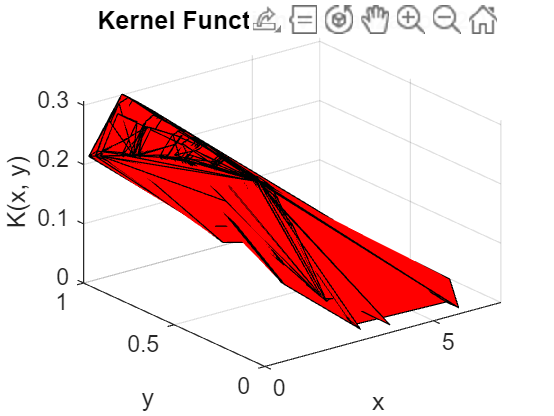

Unrecognized function or variable 'x'.


figure()
surf(Xsecret, Ysecret, K, 'FaceColor', 'r');
hold on;
%surf(Xsecret, ymu2D, K2, 'FaceColor', 'g');
hold off;
xlabel('x');
ylabel('y');
zlabel('K(x, y)');
title('Kernel Function Visualization 2D');

#### materniso covariance

meanfunc = [];                    % empty: don't use a mean function
covfunc = {@covMaterniso, 3}; ell = 1.9174; sf = 0.611380; 
%covfunc = {@covDot,'iso'}; hypL.cov = log(0.4);
likfunc = @likGauss;  
hyp = struct('mean', [], 'cov', log([ell; sf]), 'lik', -1);


%use CV to have ten times in different subsets 
mape_values= zeros(10,1)

mape_values =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp2D = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp2D, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);
    mape_values(k) = calculateMAPE(ytest, ymu, n )
end 

Function evaluation      0;  Value 6.491469e+01
Function evaluation     10;  Value -2.883959e+02
Function evaluation     13;  Value -3.432649e+02
Function evaluation     17;  Value -3.446445e+02
Function evaluation     21;  Value -3.506017e+02
Function evaluation     24;  Value -3.511976e+02
Function evaluation     26;  Value -3.515938e+02
Function evaluation     29;  Value -3.516292e+02
Function evaluation     30;  Value -3.516645e+02
Function evaluation     32;  Value -3.516858e+02
Function evaluation     35;  Value -3.517891e+02
Function evaluation     37;  Value -3.518227e+02
Function evaluation     39;  Value -3.518397e+02
Function evaluation     41;  Value -3.518410e+02
Function evaluation     43;  Value -3.518416e+02
Function evaluation     46;  Value -3.518438e+02
Function evaluation     48;  Value -3.518451e+02
Function evaluation     50;  Value -3.518461e+02
Function evaluation     53;  Value -3.518461e+02
Function evaluation     55;  Value -3.518461e+02
Function evaluation  

mape_values =    12.2276
         0
         0
         0
         0
         0
         0
         0
         0
         0


Function evaluation      0;  Value 6.648895e+01
Function evaluation     10;  Value -2.608244e+02
Function evaluation     13;  Value -3.246541e+02
Function evaluation     16;  Value -3.259362e+02
Function evaluation     17;  Value -3.272227e+02
Function evaluation     19;  Value -3.289703e+02
Function evaluation     21;  Value -3.315157e+02
Function evaluation     22;  Value -3.334917e+02
Function evaluation     25;  Value -3.337216e+02
Function evaluation     27;  Value -3.338968e+02
Function evaluation     30;  Value -3.339004e+02
Function evaluation     32;  Value -3.339007e+02
Function evaluation     34;  Value -3.339008e+02
Function evaluation     38;  Value -3.339014e+02
Function evaluation     40;  Value -3.339017e+02
Function evaluation     42;  Value -3.339020e+02
Function evaluation     45;  Value -3.339020e+02
Function evaluation     47;  Value -3.339020e+02
Function evaluation     49;  Value -3.339020e+02
Function evaluation     51;  Value -3.339020e+02
Function evaluation  

mape_values =    12.2276
    6.9254
         0
         0
         0
         0
         0
         0
         0
         0


Function evaluation      0;  Value 6.697280e+01
Function evaluation     10;  Value -2.591374e+02
Function evaluation     13;  Value -3.239328e+02
Function evaluation     16;  Value -3.259548e+02
Function evaluation     18;  Value -3.272469e+02
Function evaluation     20;  Value -3.290114e+02
Function evaluation     22;  Value -3.305811e+02
Function evaluation     24;  Value -3.328667e+02
Function evaluation     28;  Value -3.332006e+02
Function evaluation     30;  Value -3.332634e+02
Function evaluation     32;  Value -3.332654e+02
Function evaluation     34;  Value -3.332669e+02
Function evaluation     36;  Value -3.332674e+02
Function evaluation     38;  Value -3.332675e+02
Function evaluation     40;  Value -3.332675e+02
Function evaluation     43;  Value -3.332678e+02
Function evaluation     46;  Value -3.332678e+02
Function evaluation     48;  Value -3.332679e+02
Function evaluation     51;  Value -3.332679e+02
Function evaluation     53;  Value -3.332679e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
         0
         0
         0
         0
         0
         0
         0


Function evaluation      0;  Value 6.560849e+01
Function evaluation     10;  Value -2.740635e+02
Function evaluation     13;  Value -3.301848e+02
Function evaluation     16;  Value -3.311716e+02
Function evaluation     18;  Value -3.324628e+02
Function evaluation     20;  Value -3.339092e+02
Function evaluation     22;  Value -3.365750e+02
Function evaluation     25;  Value -3.372457e+02
Function evaluation     27;  Value -3.374706e+02
Function evaluation     31;  Value -3.375026e+02
Function evaluation     33;  Value -3.375254e+02
Function evaluation     35;  Value -3.375280e+02
Function evaluation     37;  Value -3.375286e+02
Function evaluation     39;  Value -3.375287e+02
Function evaluation     40;  Value -3.375288e+02
Function evaluation     43;  Value -3.375297e+02
Function evaluation     45;  Value -3.375298e+02
Function evaluation     47;  Value -3.375298e+02
Function evaluation     50;  Value -3.375298e+02
Function evaluation     53;  Value -3.375298e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
         0
         0
         0
         0
         0
         0


Function evaluation      0;  Value 6.691798e+01
Function evaluation     10;  Value -2.567223e+02
Function evaluation     13;  Value -3.194522e+02
Function evaluation     16;  Value -3.216792e+02
Function evaluation     18;  Value -3.233871e+02
Function evaluation     20;  Value -3.254373e+02
Function evaluation     22;  Value -3.275274e+02
Function evaluation     24;  Value -3.297728e+02
Function evaluation     28;  Value -3.300637e+02
Function evaluation     30;  Value -3.303901e+02
Function evaluation     33;  Value -3.303907e+02
Function evaluation     35;  Value -3.303908e+02
Function evaluation     37;  Value -3.303908e+02
Function evaluation     40;  Value -3.303909e+02
Function evaluation     43;  Value -3.303910e+02
Function evaluation     45;  Value -3.303911e+02
Function evaluation     47;  Value -3.303911e+02
Function evaluation     49;  Value -3.303911e+02
Function evaluation     51;  Value -3.303911e+02
Function evaluation     53;  Value -3.303911e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
         0
         0
         0
         0
         0


Function evaluation      0;  Value 6.613307e+01
Function evaluation     10;  Value -2.650160e+02
Function evaluation     13;  Value -3.245664e+02
Function evaluation     16;  Value -3.263243e+02
Function evaluation     18;  Value -3.276751e+02
Function evaluation     20;  Value -3.295315e+02
Function evaluation     21;  Value -3.316622e+02
Function evaluation     22;  Value -3.336340e+02
Function evaluation     26;  Value -3.339032e+02
Function evaluation     28;  Value -3.341082e+02
Function evaluation     30;  Value -3.341812e+02
Function evaluation     32;  Value -3.341833e+02
Function evaluation     35;  Value -3.341834e+02
Function evaluation     39;  Value -3.341853e+02
Function evaluation     41;  Value -3.341867e+02
Function evaluation     44;  Value -3.341867e+02
Function evaluation     46;  Value -3.341867e+02
Function evaluation     49;  Value -3.341867e+02
Function evaluation     54;  Value -3.341867e+02
Function evaluation     57;  Value -3.341867e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
   10.2787
         0
         0
         0
         0


Function evaluation      0;  Value 6.697956e+01
Function evaluation     10;  Value -2.633470e+02
Function evaluation     13;  Value -3.407790e+02
Function evaluation     16;  Value -3.460744e+02
Function evaluation     18;  Value -3.477766e+02
Function evaluation     19;  Value -3.492390e+02
Function evaluation     22;  Value -3.498523e+02
Function evaluation     24;  Value -3.515409e+02
Function evaluation     27;  Value -3.517254e+02
Function evaluation     29;  Value -3.517472e+02
Function evaluation     32;  Value -3.517490e+02
Function evaluation     36;  Value -3.517731e+02
Function evaluation     38;  Value -3.517844e+02
Function evaluation     40;  Value -3.517945e+02
Function evaluation     42;  Value -3.517948e+02
Function evaluation     44;  Value -3.517949e+02
Function evaluation     47;  Value -3.517954e+02
Function evaluation     50;  Value -3.517955e+02
Function evaluation     52;  Value -3.517955e+02
Function evaluation     55;  Value -3.517955e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
   10.2787
    9.4094
         0
         0
         0


Function evaluation      0;  Value 6.575536e+01
Function evaluation     10;  Value -2.768202e+02
Function evaluation     13;  Value -3.349032e+02
Function evaluation     16;  Value -3.355860e+02
Function evaluation     18;  Value -3.368517e+02
Function evaluation     19;  Value -3.381069e+02
Function evaluation     21;  Value -3.403482e+02
Function evaluation     24;  Value -3.407180e+02
Function evaluation     26;  Value -3.411590e+02
Function evaluation     28;  Value -3.412571e+02
Function evaluation     31;  Value -3.412574e+02
Function evaluation     33;  Value -3.412575e+02
Function evaluation     36;  Value -3.412580e+02
Function evaluation     38;  Value -3.412580e+02
Function evaluation     40;  Value -3.412581e+02
Function evaluation     43;  Value -3.412581e+02
Function evaluation     45;  Value -3.412581e+02
Function evaluation     47;  Value -3.412581e+02
Function evaluation     50;  Value -3.412581e+02
Function evaluation     52;  Value -3.412581e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
   10.2787
    9.4094
    9.9864
         0
         0


Function evaluation      0;  Value 6.668585e+01
Function evaluation     10;  Value -2.712606e+02
Function evaluation     13;  Value -3.410725e+02
Function evaluation     16;  Value -3.452030e+02
Function evaluation     18;  Value -3.467209e+02
Function evaluation     20;  Value -3.478475e+02
Function evaluation     22;  Value -3.483616e+02
Function evaluation     24;  Value -3.495547e+02
Function evaluation     27;  Value -3.496667e+02
Function evaluation     29;  Value -3.497540e+02
Function evaluation     31;  Value -3.497551e+02
Function evaluation     33;  Value -3.497556e+02
Function evaluation     35;  Value -3.497558e+02
Function evaluation     37;  Value -3.497558e+02
Function evaluation     39;  Value -3.497558e+02
Function evaluation     41;  Value -3.497559e+02
Function evaluation     43;  Value -3.497559e+02
Function evaluation     46;  Value -3.497559e+02
Function evaluation     48;  Value -3.497559e+02
Function evaluation     50;  Value -3.497560e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
   10.2787
    9.4094
    9.9864
    8.9851
         0


Function evaluation      0;  Value 6.655273e+01
Function evaluation     10;  Value -2.649506e+02
Function evaluation     13;  Value -3.271475e+02
Function evaluation     16;  Value -3.282752e+02
Function evaluation     18;  Value -3.297022e+02
Function evaluation     20;  Value -3.316186e+02
Function evaluation     22;  Value -3.350719e+02
Function evaluation     24;  Value -3.365242e+02
Function evaluation     27;  Value -3.369916e+02
Function evaluation     30;  Value -3.370410e+02
Function evaluation     32;  Value -3.370411e+02
Function evaluation     34;  Value -3.370411e+02
Function evaluation     36;  Value -3.370411e+02
Function evaluation     38;  Value -3.370411e+02
Function evaluation     41;  Value -3.370411e+02
Function evaluation     43;  Value -3.370411e+02
Function evaluation     45;  Value -3.370411e+02
Function evaluation     48;  Value -3.370411e+02
Function evaluation     50;  Value -3.370411e+02
Function evaluation     52;  Value -3.370411e+02
Function evaluation  

mape_values =    12.2276
    6.9254
    7.8797
    8.9240
    4.0859
   10.2787
    9.4094
    9.9864
    8.9851
    7.1282


mape_matern = mean(mape_values)

mape_matern = 8.5830

mean_var = mean(ys2)

mean_var = 0.0039

#### doing CV with different kernels is complicated as they all have different param

meanfunc = [];                    % empty: don't use a mean function
cov_se = @covSEiso; hyp.cov = [0; 0];
cov_mat = {@covMaterniso, 3}; ell = 1/4; sf = 1; %hyp.cov = log([ell; sf]);
%infmet = @infLaplace;
likfunc = @likGauss;sn = 0.1; hyp.lik = log(sn);
% gaussian,laplce, 
% what we wanna test for ;  @likT has two paraam
kernels = {cov_se; cov_mat} %..., kernelN}; % list of kernels to compare

kernels = 2×1 cell array
    {@covSEiso}
    {1×2 cell }


best_kernel = [];
best_nlZ = Inf;
likvalues = zeros(length(kernels), numtestsets);

% for i = 1:length(kernels)
%     for k= 1: numtestsets
%         %extract data first 
%         xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
%         xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
%         % train GP with kernel i
%         [nlZ, ~] = gp(hyp, inf, meanfunc,kernels(i) ,likfunc, xtrain, ytrain);
% 
%         % check if this model is better than the best one so far
%         if nlZ < best_nlZ
%             best_nlZ = nlZ;
%             best_kernel = kernels{i};
%         end
%         %calculate prediction 10 inner repetitions
%         latent_vars = zeros(10,2);
%         mape_avg =zeros(10,1);
%         for j= 1: 10
%             [ymu ,ys2 ,fmu, fs2 ,lp] = gp(hyp, inf, meanfunc,covfunc , kernels{i}, xtrain, ytrain, xtest, ytest);
%             n= size(ytest, 1); mape_avg(j,1) = calculateMAPE(ytest, ymu,n)
%             latent_vars(j,1) = fmu; latent_vars(j,2) = fs2;
%         end 
% 
%         likvalues(i,k) = mean(mape_avg);
%     end
% end

#### testing differnt likelihood function

% hyp.cov [lengthscale, signal st]
covfunc = @covSEiso; hyp.cov = [0; 0]; hyp.lik = [log(0.1), 2]; likfunc = @likT;
  [m ,s2] = gp(hyp, @infLaplace, [], covfunc, likfunc, x, y, xs);

Unrecognized function or variable 'x'.

  f = [m+2*sqrt(s2); flipdim(m-2*sqrt(s2),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; plot(xs, m); plot(x, y, '+')
  mape = calculateMAPE(ys, m, size(ys, 1))

%C = covSEiso(Xtrain)
meanfunc = [];                    % empty: don't use a mean function
covfunc = @covSEiso;              % Squared Exponental covariance function
likfunc = @likGauss;              % Gaussian likelihood

%2 log -param for SEiso
%always three param for theHYP STRUCT
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);

 %100 evaluations allowed 
hypE = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);

%  making predictions 
[ymu ,ys2 ,fmu, fs2, lp] = gp(hypE, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, Xtest);



cov = hypE.cov;
ls = exp(cov(1))
ns = exp(cov(2))

kernel = @(x, y) ns^2 * exp(-0.5 * (x-y).^2 / ls^2);

% create a grid of points to evaluate the kernel function

% evaluate the kernel function at each point in the grid
K = kernel(XVal, YVal);

K2 = kernel(XVal, ymu);

% create a surface plot
figure()
surf(XVal, YVal, K);
hold on;
surf(XVal, ymu, K2);
hold off;
% hold on 
%  plot(ymu + 2*sqrt(ys2))
%  hold off
xlabel('x');
ylabel('y');
zlabel('K(x, y)');
title('Kernel Function Visualization');

lfrom hyp2; **cov (SEiso): the lengthscale is exp^0.349 = 2.814 a**nd signal std exp ^-0.8636 = 0.4216

lik: teh noise std is exp(-3.9395) =  0.0195. Showing that there is really very small noise

SEiso: is hyperparamatrized as: x, z correspond to [0, 0] passed in the hyperparam struct    log(0) = 1 l corresponds to length-scale and signal std dev to be initialized to 1

k(x,z) = sf^2 * exp(-(x-z)'*inv(P)*(x-z)/2) 

USING se -ARD 

kernel is squared exponential , meaning that the mu and st that we get by minimize the marginal likelihood correspond to the best function `mu+2*sqrt(s2) `

% hyperparameters are:
%
% hyp = [ log(ell_1)
%         log(ell_2)
%          .
%         log(ell_D)
%         log(sf) ]


 The covariance function is parameterized as: k(x,z) = sf^2 * exp(-(x-z)'*inv(P)*(x-z)/2)

`where the P matrix is diagonal with ARD parameters ell_1^2,...,ell_D^2:`

` D is the dimension of the input space and sf2 is the signal variance.`

%original problem statement
ell = 100; sf = 8.2157; 
 
covfunc = @covSEard; hyp.cov = log(ell);
meanfunc= []; hyp.mean = [];
likfunc= @likGauss; hyp.lik = log(0.1);

ell_values = linspace(1, 10000, 20); % they have the same length 
sf_values = linspace(1/1000, 10, 20);
ell_loss = zeros(length(ell_values), numtestsets);
sf_loss = zeros(length(ell_values), numtestsets);

%use CV
for i= 1: length(ell_values)
    for k = 1:numtestsets
   % Extract the training and test set from the partition object
        Xtrain = XT(cv.training(k),:); Ytrain = YT(cv.training(k),:);
        Xtest = XT(cv.test(k),:); Ytest = YT(cv.test(k),:);

        %set ell and sf (very las)
        ellD = zeros(1, size(Xtrain, 2) +1); ellD(:,:) = ell_values(i); ellD(1,end) =log(sf) ;
        %ellD(1,end) = sf_values(i);
        hyp.cov = log(ellD)
        mape_values = zeros(1,10);
        %10 inner repetitions 
        for j = 1:10 
            hypARD = minimize(hyp, @gp, -40, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);
            
            %predict 
            [ymu ,ys2 ,fmu, fs2, lp] = gp(hypARD, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, Xtest, Ytest);
             n = size(Ytest, 1);
             mape_values(j) = calculateMAPE(Ytest, ymu, n )
        end 
        ell_loss(i, k) =mean(mape_values)
     end
end 

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383         0         0         0         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383         0         0         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383         0         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383    5.4383         0         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383         0         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383         0         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383         0


Function evaluation      0;  Value 3.295055e+01
Function evaluation     10;  Value -2.436660e+02
Function evaluation     15;  Value -2.963852e+02
Function evaluation     18;  Value -3.093861e+02
Function evaluation     20;  Value -3.434699e+02
Function evaluation     22;  Value -4.009635e+02
Function evaluation     25;  Value -4.518509e+02
Function evaluation     28;  Value -4.748173e+02
Function evaluation     31;  Value -4.812487e+02
Function evaluation     33;  Value -4.993809e+02
Function evaluation     36;  Value -5.056527e+02
Function evaluation     38;  Value -5.088534e+02
Function evaluation     39;  Value -5.122726e+02


mape_values =     5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383    5.4383


ell_loss =     5.4383         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487         0         0         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487         0         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487    8.7487         0         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487         0         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487         0         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487         0


Function evaluation      0;  Value 4.595237e+01
Function evaluation     10;  Value -2.206945e+02
Function evaluation     14;  Value -2.802567e+02
Function evaluation     17;  Value -2.959308e+02
Function evaluation     19;  Value -3.252178e+02
Function evaluation     22;  Value -3.998899e+02
Function evaluation     23;  Value -4.482506e+02
Function evaluation     26;  Value -4.706140e+02
Function evaluation     28;  Value -4.796248e+02
Function evaluation     30;  Value -4.939450e+02
Function evaluation     32;  Value -5.092372e+02
Function evaluation     34;  Value -5.163451e+02
Function evaluation     36;  Value -5.181981e+02
Function evaluation     37;  Value -5.200598e+02
Function evaluation     39;  Value -5.210492e+02


mape_values =     8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487    8.7487


ell_loss =     5.4383    8.7487         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178         0         0         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178         0         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178    7.1178         0         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178         0         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178         0         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178         0


Function evaluation      0;  Value 5.126148e+01
Function evaluation     10;  Value -2.166413e+02
Function evaluation     16;  Value -2.835383e+02
Function evaluation     19;  Value -2.998135e+02
Function evaluation     21;  Value -3.330111e+02
Function evaluation     24;  Value -4.059738e+02
Function evaluation     25;  Value -4.538354e+02
Function evaluation     28;  Value -4.723175e+02
Function evaluation     30;  Value -4.786902e+02
Function evaluation     34;  Value -5.138656e+02
Function evaluation     36;  Value -5.245950e+02
Function evaluation     39;  Value -5.258954e+02


mape_values =     7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178    7.1178


ell_loss =     5.4383    8.7487    7.1178         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549         0         0         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549         0         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549    6.0549         0         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549         0         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549         0         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549         0


Function evaluation      0;  Value 4.101797e+01
Function evaluation     10;  Value -2.298392e+02
Function evaluation     15;  Value -2.862014e+02
Function evaluation     17;  Value -3.018878e+02
Function evaluation     19;  Value -3.344061e+02
Function evaluation     21;  Value -3.931460e+02
Function evaluation     23;  Value -4.597211e+02
Function evaluation     27;  Value -4.788740e+02
Function evaluation     29;  Value -4.873727e+02
Function evaluation     31;  Value -4.964405e+02
Function evaluation     33;  Value -5.006206e+02
Function evaluation     35;  Value -5.055054e+02
Function evaluation     37;  Value -5.088922e+02
Function evaluation     39;  Value -5.179348e+02


mape_values =     6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549    6.0549


ell_loss =     5.4383    8.7487    7.1178    6.0549         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829    5.1829         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829    5.1829    5.1829         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829    5.1829    5.1829    5.1829         0         0         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829    5.1829    5.1829    5.1829    5.1829         0         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values =     5.1829    5.1829    5.1829    5.1829    5.1829    5.1829         0         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values = 1×10
    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829         0         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values = 1×10
    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829         0         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values = 1×10
    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829         0


Function evaluation      0;  Value 5.335628e+01
Function evaluation     10;  Value -2.113790e+02
Function evaluation     15;  Value -2.767984e+02
Function evaluation     17;  Value -2.949793e+02
Function evaluation     19;  Value -3.306895e+02
Function evaluation     21;  Value -3.743011e+02
Function evaluation     23;  Value -4.668645e+02
Function evaluation     26;  Value -4.742031e+02
Function evaluation     28;  Value -4.885775e+02
Function evaluation     29;  Value -5.005613e+02
Function evaluation     31;  Value -5.054416e+02
Function evaluation     33;  Value -5.127086e+02
Function evaluation     35;  Value -5.150088e+02
Function evaluation     37;  Value -5.192552e+02
Function evaluation     39;  Value -5.215528e+02


mape_values = 1×10
    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829    5.1829


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105         0         0         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105         0         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105         0         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105         0         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105         0         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105         0


Function evaluation      0;  Value 4.915445e+01
Function evaluation     10;  Value -2.193720e+02
Function evaluation     14;  Value -2.803293e+02
Function evaluation     16;  Value -2.979920e+02
Function evaluation     18;  Value -3.301014e+02
Function evaluation     21;  Value -3.991165e+02
Function evaluation     23;  Value -4.601460e+02
Function evaluation     27;  Value -4.852265e+02
Function evaluation     30;  Value -4.909033e+02
Function evaluation     32;  Value -5.019326e+02
Function evaluation     34;  Value -5.071170e+02
Function evaluation     36;  Value -5.105618e+02
Function evaluation     38;  Value -5.186358e+02


mape_values = 1×10
    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105    5.1105


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085         0         0         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085         0         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085         0         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085         0         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085         0         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085         0


Function evaluation      0;  Value 5.364020e+01
Function evaluation     10;  Value -2.168732e+02
Function evaluation     16;  Value -2.999092e+02
Function evaluation     18;  Value -3.222599e+02
Function evaluation     19;  Value -3.478858e+02
Function evaluation     21;  Value -3.788690e+02
Function evaluation     23;  Value -4.601784e+02
Function evaluation     26;  Value -4.680017e+02
Function evaluation     28;  Value -4.853526e+02
Function evaluation     30;  Value -4.961535e+02
Function evaluation     32;  Value -5.042234e+02
Function evaluation     34;  Value -5.104556e+02
Function evaluation     36;  Value -5.132022e+02
Function evaluation     40;  Value -5.327950e+02


mape_values = 1×10
    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085    7.5085


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514         0         0         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514         0         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514         0         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514         0         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514         0         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514         0


Function evaluation      0;  Value 4.116155e+01
Function evaluation     10;  Value -2.337486e+02
Function evaluation     15;  Value -2.877518e+02
Function evaluation     17;  Value -3.035255e+02
Function evaluation     19;  Value -3.349996e+02
Function evaluation     21;  Value -3.887716e+02
Function evaluation     23;  Value -4.718320e+02
Function evaluation     26;  Value -4.804335e+02
Function evaluation     28;  Value -4.952812e+02
Function evaluation     30;  Value -5.054856e+02
Function evaluation     32;  Value -5.173639e+02
Function evaluation     36;  Value -5.188777e+02
Function evaluation     39;  Value -5.266647e+02


mape_values = 1×10
   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514   11.8514


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606         0         0         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606         0         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606         0         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606         0         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606         0         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606         0


Function evaluation      0;  Value 4.940888e+01
Function evaluation     10;  Value -2.246094e+02
Function evaluation     16;  Value -3.006695e+02
Function evaluation     19;  Value -3.176563e+02
Function evaluation     21;  Value -3.494024e+02
Function evaluation     24;  Value -4.247707e+02
Function evaluation     26;  Value -4.560465e+02
Function evaluation     28;  Value -4.749797e+02
Function evaluation     30;  Value -4.880418e+02
Function evaluation     33;  Value -5.138457e+02
Function evaluation     37;  Value -5.200643e+02
Function evaluation     39;  Value -5.237856e+02


mape_values = 1×10
    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606    6.3606


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328         0         0         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328         0         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328         0         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328         0         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328         0         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328         0


Function evaluation      0;  Value 4.463713e+01
Function evaluation     10;  Value -2.244643e+02
Function evaluation     15;  Value -2.827972e+02
Function evaluation     18;  Value -2.971569e+02
Function evaluation     20;  Value -3.305113e+02
Function evaluation     23;  Value -3.909154e+02
Function evaluation     26;  Value -4.434135e+02
Function evaluation     29;  Value -4.703240e+02
Function evaluation     31;  Value -4.802682e+02
Function evaluation     33;  Value -5.029345e+02
Function evaluation     35;  Value -5.104867e+02
Function evaluation     37;  Value -5.164835e+02
Function evaluation     39;  Value -5.196020e+02


mape_values = 1×10
    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328    6.3328


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691         0         0         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691         0         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691         0         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691         0         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691         0         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691         0


Function evaluation      0;  Value 4.182179e+02
Function evaluation     10;  Value 2.926673e+01
Function evaluation     17;  Value -2.006315e+02
Function evaluation     22;  Value -2.016551e+02
Function evaluation     24;  Value -2.050740e+02
Function evaluation     26;  Value -2.067274e+02
Function evaluation     29;  Value -2.208254e+02
Function evaluation     31;  Value -2.230928e+02
Function evaluation     32;  Value -2.252556e+02
Function evaluation     34;  Value -2.255740e+02
Function evaluation     36;  Value -2.260436e+02


mape_values = 1×10
   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691   28.2691


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430         0         0         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430         0         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430         0         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430         0         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430         0         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430         0


Function evaluation      0;  Value 4.136457e+02
Function evaluation     10;  Value 2.847170e+01
Function evaluation     17;  Value -1.878655e+02
Function evaluation     22;  Value -1.887395e+02
Function evaluation     24;  Value -1.914357e+02
Function evaluation     27;  Value -2.007279e+02
Function evaluation     29;  Value -2.052071e+02
Function evaluation     32;  Value -2.095287e+02
Function evaluation     35;  Value -2.096737e+02


mape_values = 1×10
   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430   28.6430


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433         0         0         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433         0         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433         0         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433         0         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433         0         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433         0


Function evaluation      0;  Value 4.148400e+02
Function evaluation     10;  Value 2.904302e+01
Function evaluation     15;  Value -1.935153e+02
Function evaluation     18;  Value -1.940539e+02
Function evaluation     21;  Value -1.974298e+02
Function evaluation     24;  Value -1.976570e+02
Function evaluation     29;  Value -2.089593e+02
Function evaluation     32;  Value -2.110502e+02
Function evaluation     35;  Value -2.139575e+02
Function evaluation     38;  Value -2.142986e+02


mape_values = 1×10
   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433   27.5433


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001         0         0         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001         0         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001         0         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001         0         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001         0         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001         0


Function evaluation      0;  Value 4.168869e+02
Function evaluation     10;  Value 2.851981e+01
Function evaluation     16;  Value -1.999369e+02
Function evaluation     21;  Value -2.012947e+02
Function evaluation     23;  Value -2.062105e+02
Function evaluation     26;  Value -2.064350e+02
Function evaluation     31;  Value -2.125042e+02
Function evaluation     35;  Value -2.139480e+02
Function evaluation     39;  Value -2.215268e+02


mape_values = 1×10
   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001   46.1001


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932         0         0         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932         0         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932         0         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932         0         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932         0         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932         0


Function evaluation      0;  Value 4.170504e+02
Function evaluation     10;  Value 2.965034e+01
Function evaluation     17;  Value -1.893828e+02
Function evaluation     22;  Value -1.900072e+02
Function evaluation     25;  Value -1.922452e+02
Function evaluation     26;  Value -1.944066e+02
Function evaluation     29;  Value -2.046322e+02
Function evaluation     32;  Value -2.060860e+02
Function evaluation     34;  Value -2.077261e+02
Function evaluation     36;  Value -2.083850e+02
Function evaluation     38;  Value -2.088584e+02
Function evaluation     40;  Value -2.090623e+02


mape_values = 1×10
   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932   22.6932


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859         0         0         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859         0         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859         0         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859         0         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859         0         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859         0


Function evaluation      0;  Value 4.060097e+02
Function evaluation     10;  Value 2.726861e+01
Function evaluation     15;  Value -1.997994e+02
Function evaluation     20;  Value -2.011946e+02
Function evaluation     22;  Value -2.047012e+02
Function evaluation     25;  Value -2.049707e+02
Function evaluation     30;  Value -2.151065e+02
Function evaluation     32;  Value -2.172364e+02
Function evaluation     34;  Value -2.189963e+02
Function evaluation     37;  Value -2.191554e+02
Function evaluation     40;  Value -2.202984e+02


mape_values = 1×10
   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859   33.3859


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588         0         0         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588         0         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588         0         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588         0         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588         0         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588         0


Function evaluation      0;  Value 4.064930e+02
Function evaluation     10;  Value 2.757482e+01
Function evaluation     15;  Value -1.892848e+02
Function evaluation     20;  Value -1.899441e+02
Function evaluation     23;  Value -1.926638e+02
Function evaluation     26;  Value -1.930160e+02
Function evaluation     31;  Value -2.021081e+02
Function evaluation     33;  Value -2.056380e+02
Function evaluation     35;  Value -2.087564e+02
Function evaluation     37;  Value -2.095308e+02
Function evaluation     39;  Value -2.101816e+02


mape_values = 1×10
   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588   31.4588


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470         0         0         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470         0         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470         0         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470         0         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470         0         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470         0


Function evaluation      0;  Value 4.042362e+02
Function evaluation     10;  Value 2.726823e+01
Function evaluation     15;  Value -2.000176e+02
Function evaluation     20;  Value -2.011730e+02
Function evaluation     22;  Value -2.038738e+02
Function evaluation     26;  Value -2.043764e+02
Function evaluation     31;  Value -2.191391e+02
Function evaluation     35;  Value -2.192662e+02
Function evaluation     39;  Value -2.221430e+02


mape_values = 1×10
   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470   31.6470


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646         0         0         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646         0         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646         0         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646         0         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646         0         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646         0


Function evaluation      0;  Value 4.226036e+02
Function evaluation     10;  Value 3.055261e+01
Function evaluation     15;  Value -1.984489e+02
Function evaluation     19;  Value -1.989306e+02
Function evaluation     22;  Value -2.019248e+02
Function evaluation     25;  Value -2.021509e+02
Function evaluation     30;  Value -2.131682e+02
Function evaluation     33;  Value -2.147299e+02
Function evaluation     36;  Value -2.176548e+02
Function evaluation     38;  Value -2.188418e+02
Function evaluation     40;  Value -2.197934e+02


mape_values = 1×10
   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646   35.3646


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 6.2677 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883         0         0         0         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883         0         0         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883         0         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883         0         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883         0         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883         0         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883         0


Function evaluation      0;  Value 4.093554e+02
Function evaluation     10;  Value 2.762616e+01
Function evaluation     15;  Value -1.907186e+02
Function evaluation     18;  Value -1.912683e+02
Function evaluation     21;  Value -1.943310e+02
Function evaluation     24;  Value -1.945654e+02
Function evaluation     30;  Value -2.062133e+02
Function evaluation     33;  Value -2.075471e+02
Function evaluation     37;  Value -2.115543e+02
Function evaluation     40;  Value -2.119395e+02


mape_values = 1×10
   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883   42.8883


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449         0         0         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449         0         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449         0         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449         0         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449         0         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449         0


Function evaluation      0;  Value 5.748784e+02
Function evaluation     10;  Value 4.329464e+01
Function evaluation     14;  Value 3.990788e+01
Function evaluation     16;  Value 3.935066e+01
Function evaluation     26;  Value -1.153364e+02
Function evaluation     30;  Value -1.190518e+02
Function evaluation     35;  Value -2.010075e+02
Function evaluation     37;  Value -2.034932e+02


mape_values = 1×10
   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449   41.4449


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188         0         0         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188         0         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188         0         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188         0         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188         0         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188         0


Function evaluation      0;  Value 5.670531e+02
Function evaluation     10;  Value 4.225969e+01
Function evaluation     14;  Value 3.868354e+01
Function evaluation     16;  Value 3.789591e+01
Function evaluation     24;  Value -1.232215e+02
Function evaluation     28;  Value -1.276209e+02
Function evaluation     32;  Value -1.878253e+02
Function evaluation     35;  Value -1.881613e+02
Function evaluation     37;  Value -1.884498e+02
Function evaluation     40;  Value -1.897936e+02


mape_values = 1×10
   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188   33.4188


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145         0         0         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145         0         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145         0         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145         0         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145         0         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145         0


Function evaluation      0;  Value 5.721783e+02
Function evaluation     10;  Value 4.341018e+01
Function evaluation     14;  Value 3.952830e+01
Function evaluation     16;  Value 3.849946e+01
Function evaluation     26;  Value -1.360082e+02
Function evaluation     30;  Value -1.411316e+02
Function evaluation     34;  Value -1.938640e+02
Function evaluation     38;  Value -1.943866e+02
Function evaluation     40;  Value -1.949976e+02


mape_values = 1×10
   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145   28.9145


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725         0         0         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725         0         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725         0         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725         0         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725         0         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725         0


Function evaluation      0;  Value 5.656749e+02
Function evaluation     10;  Value 4.155436e+01
Function evaluation     14;  Value 3.846504e+01
Function evaluation     18;  Value 3.805087e+01
Function evaluation     26;  Value -1.426165e+02
Function evaluation     30;  Value -1.456299e+02
Function evaluation     35;  Value -2.032348e+02
Function evaluation     37;  Value -2.045612e+02
Function evaluation     39;  Value -2.056418e+02


mape_values = 1×10
   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725   51.0725


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660         0         0         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660         0         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660         0         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660         0         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660         0         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660         0


Function evaluation      0;  Value 5.775012e+02
Function evaluation     10;  Value 4.421561e+01
Function evaluation     14;  Value 4.055508e+01
Function evaluation     16;  Value 3.979408e+01
Function evaluation     24;  Value -1.238798e+02
Function evaluation     28;  Value -1.289338e+02
Function evaluation     31;  Value -1.884483e+02
Function evaluation     34;  Value -1.885074e+02
Function evaluation     38;  Value -1.894340e+02


mape_values = 1×10
   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660   27.4660


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169         0         0         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169         0         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169         0         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169         0         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169         0         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169         0


Function evaluation      0;  Value 5.606053e+02
Function evaluation     10;  Value 4.130443e+01
Function evaluation     14;  Value 3.747883e+01
Function evaluation     16;  Value 3.628276e+01
Function evaluation     24;  Value -1.444463e+02
Function evaluation     28;  Value -1.498651e+02
Function evaluation     32;  Value -2.011524e+02
Function evaluation     36;  Value -2.017229e+02
Function evaluation     38;  Value -2.021724e+02


mape_values = 1×10
   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169   38.5169


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509         0         0         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509         0         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509         0         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509         0         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509         0         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509         0


Function evaluation      0;  Value 5.627076e+02
Function evaluation     10;  Value 4.201020e+01
Function evaluation     14;  Value 3.745156e+01
Function evaluation     16;  Value 3.522019e+01
Function evaluation     22;  Value -1.617439e+02
Function evaluation     25;  Value -1.659579e+02
Function evaluation     29;  Value -1.885291e+02
Function evaluation     32;  Value -1.887776e+02
Function evaluation     35;  Value -1.896205e+02
Function evaluation     37;  Value -1.911682e+02


mape_values = 1×10
   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509   32.0509


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297         0         0         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297         0         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297         0         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297         0         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297         0         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297         0


Function evaluation      0;  Value 5.644398e+02
Function evaluation     10;  Value 4.212228e+01
Function evaluation     14;  Value 3.781428e+01
Function evaluation     16;  Value 3.598345e+01
Function evaluation     23;  Value -1.613118e+02
Function evaluation     25;  Value -1.662354e+02
Function evaluation     29;  Value -1.998909e+02
Function evaluation     32;  Value -2.003480e+02
Function evaluation     34;  Value -2.009704e+02
Function evaluation     36;  Value -2.018685e+02
Function evaluation     40;  Value -2.104713e+02


mape_values = 1×10
   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297   39.0297


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198         0         0         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198         0         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198         0         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198         0         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198         0         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198         0


Function evaluation      0;  Value 5.850765e+02
Function evaluation     10;  Value 4.537473e+01
Function evaluation     14;  Value 4.154683e+01
Function evaluation     16;  Value 4.072725e+01
Function evaluation     25;  Value -1.308084e+02
Function evaluation     29;  Value -1.353921e+02
Function evaluation     33;  Value -1.978755e+02
Function evaluation     36;  Value -1.984472e+02
Function evaluation     38;  Value -1.987478e+02


mape_values = 1×10
   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198   36.9198


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 6.9599 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330         0         0         0         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330         0         0         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330         0         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330         0         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330         0         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330         0         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330         0


Function evaluation      0;  Value 5.637913e+02
Function evaluation     10;  Value 4.177557e+01
Function evaluation     14;  Value 3.760673e+01
Function evaluation     16;  Value 3.605692e+01
Function evaluation     22;  Value -1.495026e+02
Function evaluation     24;  Value -1.544144e+02
Function evaluation     28;  Value -1.908500e+02
Function evaluation     31;  Value -1.952672e+02
Function evaluation     33;  Value -1.980054e+02
Function evaluation     35;  Value -2.057126e+02
Function evaluation     38;  Value -2.062471e+02


mape_values = 1×10
   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330   44.9330


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148         0         0         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148         0         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148         0         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148         0         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148         0         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148         0


Function evaluation      0;  Value 6.283875e+02
Function evaluation      9;  Value 6.518653e+01
Function evaluation     14;  Value 4.294745e+01
Function evaluation     23;  Value -6.343424e+01
Function evaluation     26;  Value -6.358135e+01
Function evaluation     34;  Value -2.016796e+02
Function evaluation     37;  Value -2.079908e+02
Function evaluation     39;  Value -2.126154e+02


mape_values = 1×10
   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148   35.6148


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716         0         0         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716         0         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716         0         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716         0         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716         0         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716         0


Function evaluation      0;  Value 6.200148e+02
Function evaluation      9;  Value 6.644848e+01
Function evaluation     14;  Value 4.201630e+01
Function evaluation     22;  Value -6.207725e+01
Function evaluation     25;  Value -6.222787e+01
Function evaluation     33;  Value -1.874156e+02
Function evaluation     36;  Value -1.942087e+02
Function evaluation     38;  Value -1.992624e+02
Function evaluation     40;  Value -2.066079e+02


mape_values = 1×10
   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716   28.4716


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984         0         0         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984         0         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984         0         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984         0         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984         0         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984         0


Function evaluation      0;  Value 6.271009e+02
Function evaluation      9;  Value 6.591574e+01
Function evaluation     14;  Value 4.319272e+01
Function evaluation     24;  Value -6.278002e+01
Function evaluation     27;  Value -6.294930e+01
Function evaluation     35;  Value -1.936986e+02
Function evaluation     38;  Value -1.996214e+02
Function evaluation     39;  Value -2.046393e+02


mape_values = 1×10
   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984   27.8984


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489         0         0         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489         0         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489         0         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489         0         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489         0         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489         0


Function evaluation      0;  Value 6.160699e+02
Function evaluation      9;  Value 6.639624e+01
Function evaluation     14;  Value 4.117718e+01
Function evaluation     24;  Value -6.341805e+01
Function evaluation     27;  Value -6.354300e+01
Function evaluation     37;  Value -2.029907e+02


mape_values = 1×10
   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489   47.7489


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871         0         0         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871         0         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871         0         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871         0         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871         0         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871         0


Function evaluation      0;  Value 6.328275e+02
Function evaluation      9;  Value 6.514516e+01
Function evaluation     14;  Value 4.391914e+01
Function evaluation     22;  Value -6.136246e+01
Function evaluation     25;  Value -6.152382e+01
Function evaluation     33;  Value -1.879293e+02
Function evaluation     36;  Value -1.951149e+02
Function evaluation     38;  Value -2.000750e+02
Function evaluation     40;  Value -2.063424e+02


mape_values = 1×10
   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871   23.4871


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028         0         0         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028         0         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028         0         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028         0         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028         0         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028         0


Function evaluation      0;  Value 6.138051e+02
Function evaluation      9;  Value 6.744026e+01
Function evaluation     14;  Value 4.119727e+01
Function evaluation     24;  Value -6.495145e+01
Function evaluation     27;  Value -6.511039e+01
Function evaluation     35;  Value -2.010404e+02
Function evaluation     38;  Value -2.048441e+02
Function evaluation     40;  Value -2.078205e+02


mape_values = 1×10
   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028   37.5028


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455         0         0         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455         0         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455         0         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455         0         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455         0         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455         0


Function evaluation      0;  Value 6.176379e+02
Function evaluation      9;  Value 6.735837e+01
Function evaluation     14;  Value 4.197898e+01
Function evaluation     25;  Value -6.338791e+01
Function evaluation     28;  Value -6.357537e+01
Function evaluation     36;  Value -1.882975e+02
Function evaluation     40;  Value -1.985745e+02


mape_values = 1×10
   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455   34.0455


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032         0         0         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032         0         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032         0         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032         0         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032         0         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032         0


Function evaluation      0;  Value 6.199294e+02
Function evaluation      9;  Value 6.693077e+01
Function evaluation     14;  Value 4.209745e+01
Function evaluation     24;  Value -6.547819e+01
Function evaluation     27;  Value -6.565610e+01
Function evaluation     35;  Value -2.001352e+02
Function evaluation     38;  Value -2.058712e+02
Function evaluation     39;  Value -2.106156e+02
Function evaluation     40;  Value -2.155414e+02


mape_values = 1×10
   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032   35.8032


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815         0         0         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815         0         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815         0         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815         0         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815         0         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815         0


Function evaluation      0;  Value 6.416213e+02
Function evaluation      9;  Value 6.422135e+01
Function evaluation     14;  Value 4.503223e+01
Function evaluation     23;  Value -6.245124e+01
Function evaluation     26;  Value -6.262338e+01
Function evaluation     34;  Value -1.974950e+02
Function evaluation     37;  Value -2.027602e+02
Function evaluation     38;  Value -2.072553e+02
Function evaluation     40;  Value -2.145877e+02


mape_values = 1×10
   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815   35.2815


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 7.3650 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429         0         0         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429         0         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429         0         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429         0         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429         0         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429         0


Function evaluation      0;  Value 6.176802e+02
Function evaluation      9;  Value 6.695941e+01
Function evaluation     14;  Value 4.167297e+01
Function evaluation     24;  Value -6.384907e+01
Function evaluation     27;  Value -6.402967e+01
Function evaluation     35;  Value -1.903706e+02
Function evaluation     38;  Value -1.983613e+02
Function evaluation     40;  Value -2.034438e+02


mape_values = 1×10
   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429   49.9429


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266         0         0         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266         0         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266         0         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266         0         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266         0         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266         0


Function evaluation      0;  Value 6.514016e+02
Function evaluation      9;  Value 5.822247e+01
Function evaluation     12;  Value 4.355702e+01
Function evaluation     14;  Value 4.349878e+01
Function evaluation     16;  Value 4.349079e+01
Function evaluation     29;  Value -3.323541e+01
Function evaluation     33;  Value -3.325628e+01


mape_values = 1×10
   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266   44.4266


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531         0         0         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531         0         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531         0         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531         0         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531         0         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531         0


Function evaluation      0;  Value 6.429040e+02
Function evaluation      9;  Value 5.908942e+01
Function evaluation     12;  Value 4.267350e+01
Function evaluation     14;  Value 4.258807e+01
Function evaluation     17;  Value 4.258431e+01
Function evaluation     32;  Value -4.109311e+01
Function evaluation     35;  Value -4.112455e+01


mape_values = 1×10
   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531   32.2531


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869         0         0         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869         0         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869         0         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869         0         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869         0         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869         0


Function evaluation      0;  Value 6.509578e+02
Function evaluation      9;  Value 5.867630e+01
Function evaluation     12;  Value 4.384034e+01
Function evaluation     14;  Value 4.377467e+01
Function evaluation     16;  Value 4.376496e+01
Function evaluation     28;  Value -3.350456e+01
Function evaluation     32;  Value -3.353573e+01


mape_values = 1×10
   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869   25.7869


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744         0         0         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744         0         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744         0         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744         0         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744         0         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744         0


Function evaluation      0;  Value 6.377252e+02
Function evaluation      9;  Value 5.919973e+01
Function evaluation     12;  Value 4.182238e+01
Function evaluation     13;  Value 4.171489e+01
Function evaluation     16;  Value 4.171052e+01
Function evaluation     35;  Value -2.796125e+01
Function evaluation     39;  Value -2.796800e+01


mape_values = 1×10
   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744   51.2744


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415         0         0         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415         0         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415         0         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415         0         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415         0         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415         0


Function evaluation      0;  Value 6.566945e+02
Function evaluation      9;  Value 5.819645e+01
Function evaluation     12;  Value 4.453649e+01
Function evaluation     15;  Value 4.445901e+01
Function evaluation     17;  Value 4.441952e+01
Function evaluation     30;  Value -4.714763e+01
Function evaluation     34;  Value -4.718150e+01


mape_values = 1×10
   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415   28.0415


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071         0         0         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071         0         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071         0         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071         0         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071         0         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071         0


Function evaluation      0;  Value 6.367152e+02
Function evaluation      9;  Value 5.970294e+01
Function evaluation     12;  Value 4.190531e+01
Function evaluation     13;  Value 4.178141e+01
Function evaluation     16;  Value 4.177766e+01
Function evaluation     32;  Value -5.499100e+01
Function evaluation     36;  Value -5.501251e+01


mape_values = 1×10
   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071   44.7071


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768         0         0         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768         0         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768         0         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768         0         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768         0         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768         0


Function evaluation      0;  Value 6.415523e+02
Function evaluation      9;  Value 5.956442e+01
Function evaluation     12;  Value 4.269408e+01
Function evaluation     14;  Value 4.259369e+01
Function evaluation     17;  Value 4.258895e+01
Function evaluation     31;  Value -4.271360e+01
Function evaluation     35;  Value -4.273422e+01


mape_values = 1×10
   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768   37.4768


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738         0         0         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738         0         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738         0         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738         0         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738         0         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738         0


Function evaluation      0;  Value 6.439032e+02
Function evaluation      9;  Value 5.919801e+01
Function evaluation     12;  Value 4.279281e+01
Function evaluation     14;  Value 4.270512e+01
Function evaluation     17;  Value 4.270041e+01
Function evaluation     33;  Value -4.760731e+01
Function evaluation     37;  Value -4.762822e+01


mape_values = 1×10
   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738   43.6738


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994         0         0         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994         0         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994         0         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994         0         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994         0         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994         0


Function evaluation      0;  Value 6.661100e+02
Function evaluation      9;  Value 5.760582e+01
Function evaluation     12;  Value 4.564899e+01
Function evaluation     26;  Value -9.828275e+01
Function evaluation     29;  Value -9.860025e+01
Function evaluation     36;  Value -1.835711e+02
Function evaluation     38;  Value -1.934343e+02


mape_values = 1×10
   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994   33.4994


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 7.6526 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660         0         0         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660         0         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660         0         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660         0         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660         0         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660         0


Function evaluation      0;  Value 6.410986e+02
Function evaluation      9;  Value 5.931698e+01
Function evaluation     12;  Value 4.237402e+01
Function evaluation     14;  Value 4.227379e+01
Function evaluation     17;  Value 4.226943e+01
Function evaluation     30;  Value -4.180748e+01
Function evaluation     34;  Value -4.183054e+01


mape_values = 1×10
   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660   47.0660


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698         0         0         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698         0         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698         0         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698         0         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698         0         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698         0


Function evaluation      0;  Value 6.630608e+02
Function evaluation      9;  Value 5.519107e+01
Function evaluation     12;  Value 4.376470e+01
Function evaluation     37;  Value -7.307976e+01
Function evaluation     39;  Value -9.012276e+01


mape_values = 1×10
   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698   86.4698


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239         0         0         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239         0         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239         0         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239         0         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239         0         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239         0


Function evaluation      0;  Value 6.545270e+02
Function evaluation      9;  Value 5.584432e+01
Function evaluation     12;  Value 4.285667e+01
Function evaluation     15;  Value 4.282896e+01
Function evaluation     17;  Value 4.282372e+01
Function evaluation     29;  Value -2.381890e+01
Function evaluation     33;  Value -2.382124e+01


mape_values = 1×10
   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239   75.7239


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269         0         0         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269         0         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269         0         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269         0         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269         0         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269         0


Function evaluation      0;  Value 6.631010e+02
Function evaluation      9;  Value 5.552006e+01
Function evaluation     12;  Value 4.405800e+01
Function evaluation     24;  Value -7.351188e+01
Function evaluation     27;  Value -7.371867e+01
Function evaluation     32;  Value -8.891456e+01
Function evaluation     34;  Value -9.153841e+01
Function evaluation     37;  Value -9.161335e+01
Function evaluation     39;  Value -9.167122e+01


mape_values = 1×10
   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269   46.6269


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242         0         0         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242         0         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242         0         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242         0         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242         0         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242         0


Function evaluation      0;  Value 6.486959e+02
Function evaluation      9;  Value 5.599737e+01
Function evaluation     12;  Value 4.197416e+01
Function evaluation     14;  Value 4.194285e+01
Function evaluation     17;  Value 4.194145e+01
Function evaluation     34;  Value 2.529695e+01
Function evaluation     38;  Value 2.528259e+01


mape_values = 1×10
  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242  164.8242


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527         0         0         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527         0         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527         0         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527         0         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527         0         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527         0


Function evaluation      0;  Value 6.688017e+02
Function evaluation      9;  Value 5.520256e+01
Function evaluation     12;  Value 4.476399e+01
Function evaluation     25;  Value -2.676631e+01
Function evaluation     30;  Value -2.676813e+01


mape_values = 1×10
   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527   73.0527


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304         0         0         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304         0         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304         0         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304         0         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304         0         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304         0


Function evaluation      0;  Value 6.483236e+02
Function evaluation      9;  Value 5.628159e+01
Function evaluation     12;  Value 4.206335e+01
Function evaluation     14;  Value 4.202881e+01
Function evaluation     17;  Value 4.202730e+01
Function evaluation     30;  Value -3.121392e+01
Function evaluation     34;  Value -3.121616e+01


mape_values = 1×10
   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304   83.3304


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842         0         0         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842         0         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842         0         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842         0         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842         0         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842         0


Function evaluation      0;  Value 6.537368e+02
Function evaluation      9;  Value 5.612859e+01
Function evaluation     12;  Value 4.288422e+01
Function evaluation     15;  Value 4.285458e+01
Function evaluation     17;  Value 4.284994e+01
Function evaluation     32;  Value -2.763534e+01
Function evaluation     37;  Value -2.763918e+01


mape_values = 1×10
   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842   60.0842


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042         0         0         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042         0         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042         0         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042         0         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042         0         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042         0


Function evaluation      0;  Value 6.560717e+02
Function evaluation      9;  Value 5.581766e+01
Function evaluation     12;  Value 4.298974e+01
Function evaluation     15;  Value 4.295935e+01
Function evaluation     17;  Value 4.295114e+01
Function evaluation     30;  Value -3.405837e+01
Function evaluation     35;  Value -3.406246e+01


mape_values = 1×10
   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042   89.8042


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052         0         0         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052         0         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052         0         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052         0         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052         0         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052         0


Function evaluation      0;  Value 6.785543e+02
Function evaluation      9;  Value 5.479444e+01
Function evaluation     12;  Value 4.589836e+01
Function evaluation     16;  Value 4.587690e+01
Function evaluation     18;  Value 4.582382e+01
Function evaluation     31;  Value -3.536748e+01
Function evaluation     35;  Value -3.709819e+01
Function evaluation     40;  Value -9.069223e+01


mape_values = 1×10
   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052   68.8052


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 7.8756 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963         0         0         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963         0         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963         0         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963         0         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963         0         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963         0


Function evaluation      0;  Value 6.530227e+02
Function evaluation      9;  Value 5.593819e+01
Function evaluation     12;  Value 4.255860e+01
Function evaluation     14;  Value 4.252956e+01
Function evaluation     16;  Value 4.252687e+01
Function evaluation     28;  Value -1.724211e+01
Function evaluation     33;  Value -1.724564e+01


mape_values = 1×10
   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963   92.6963


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561         0         0         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561         0         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561         0         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561         0         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561         0         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561         0


Function evaluation      0;  Value 6.696988e+02
Function evaluation      9;  Value 5.362131e+01
Function evaluation     12;  Value 4.388428e+01
Function evaluation     19;  Value 4.323559e+01
Function evaluation     21;  Value 4.299383e+01
Function evaluation     23;  Value 4.299280e+01
Function evaluation     25;  Value 4.299267e+01
Function evaluation     29;  Value 4.299085e+01
Function evaluation     32;  Value 4.299078e+01
Function evaluation     36;  Value 4.298958e+01
Function evaluation     39;  Value 4.298949e+01


mape_values = 1×10
  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561  169.9561


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991         0         0         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991         0         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991         0         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991         0         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991         0         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991         0


Function evaluation      0;  Value 6.611526e+02
Function evaluation      9;  Value 5.414988e+01
Function evaluation     12;  Value 4.296899e+01
Function evaluation     19;  Value 4.231809e+01
Function evaluation     21;  Value 4.208162e+01
Function evaluation     23;  Value 4.207698e+01
Function evaluation     26;  Value 4.207686e+01
Function evaluation     30;  Value 4.207517e+01
Function evaluation     33;  Value 4.207507e+01
Function evaluation     37;  Value 4.207308e+01
Function evaluation     40;  Value 4.207292e+01


mape_values = 1×10
  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991  200.2991


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210         0         0         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210         0         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210         0         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210         0         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210         0         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210         0


Function evaluation      0;  Value 6.700320e+02
Function evaluation      9;  Value 5.388651e+01
Function evaluation     12;  Value 4.418361e+01
Function evaluation     19;  Value 4.355754e+01
Function evaluation     21;  Value 4.327659e+01
Function evaluation     23;  Value 4.327254e+01
Function evaluation     26;  Value 4.327238e+01
Function evaluation     30;  Value 4.327005e+01
Function evaluation     33;  Value 4.326992e+01
Function evaluation     37;  Value 4.326756e+01
Function evaluation     40;  Value 4.326738e+01


mape_values = 1×10
  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210  133.6210


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003         0         0         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003         0         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003         0         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003         0         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003         0         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003         0


Function evaluation      0;  Value 6.549423e+02
Function evaluation      9;  Value 5.431327e+01
Function evaluation     12;  Value 4.207219e+01
Function evaluation     16;  Value 4.202256e+01
Function evaluation     18;  Value 4.199400e+01
Function evaluation     23;  Value 4.119138e+01
Function evaluation     27;  Value 4.118823e+01
Function evaluation     30;  Value 4.118713e+01
Function evaluation     33;  Value 4.118703e+01
Function evaluation     37;  Value 4.118647e+01
Function evaluation     39;  Value 4.118639e+01


mape_values = 1×10
  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003  232.7003


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091         0         0         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091         0         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091         0         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091         0         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091         0         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091         0


Function evaluation      0;  Value 6.756994e+02
Function evaluation      9;  Value 5.366427e+01
Function evaluation     12;  Value 4.489100e+01
Function evaluation     15;  Value 4.487285e+01
Function evaluation     17;  Value 4.482930e+01
Function evaluation     25;  Value 4.400163e+01
Function evaluation     29;  Value 4.399890e+01


mape_values = 1×10
   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091   50.3091


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400         0         0         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400         0         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400         0         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400         0         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400         0         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400         0


Function evaluation      0;  Value 6.549324e+02
Function evaluation      9;  Value 5.449099e+01
Function evaluation     12;  Value 4.216725e+01
Function evaluation     15;  Value 4.212398e+01
Function evaluation     17;  Value 4.210384e+01
Function evaluation     25;  Value 4.128567e+01
Function evaluation     28;  Value 4.126924e+01
Function evaluation     30;  Value 4.126788e+01
Function evaluation     32;  Value 4.126767e+01
Function evaluation     35;  Value 4.126590e+01
Function evaluation     37;  Value 4.126570e+01


mape_values = 1×10
  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400  159.3400


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398         0         0         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398         0         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398         0         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398         0         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398         0         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398         0


Function evaluation      0;  Value 6.606949e+02
Function evaluation      9;  Value 5.433694e+01
Function evaluation     12;  Value 4.300247e+01
Function evaluation     18;  Value 4.257897e+01
Function evaluation     20;  Value 4.216749e+01
Function evaluation     21;  Value 4.207918e+01
Function evaluation     24;  Value 4.207777e+01
Function evaluation     27;  Value 4.207256e+01
Function evaluation     29;  Value 4.207202e+01


mape_values = 1×10
   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398   46.9398


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853         0         0         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853         0         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853         0         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853         0         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853         0         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853         0


Function evaluation      0;  Value 6.630063e+02
Function evaluation      9;  Value 5.406319e+01
Function evaluation     12;  Value 4.310990e+01
Function evaluation     20;  Value 4.224590e+01
Function evaluation     23;  Value 4.220009e+01
Function evaluation     25;  Value 4.219784e+01
Function evaluation     28;  Value 4.219765e+01
Function evaluation     32;  Value 4.219534e+01
Function evaluation     35;  Value 4.219518e+01
Function evaluation     39;  Value 4.219249e+01


mape_values = 1×10
  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853  203.1853


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639         0         0         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639         0         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639         0         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639         0         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639         0         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639         0


Function evaluation      0;  Value 6.856504e+02
Function evaluation      9;  Value 5.336555e+01
Function evaluation     12;  Value 4.603172e+01
Function evaluation     15;  Value 4.602056e+01
Function evaluation     23;  Value 4.511233e+01
Function evaluation     27;  Value 4.511084e+01


mape_values = 1×10
   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639   66.4639


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 8.0579 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861         0         0         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861         0         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861         0         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861         0         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861         0         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861         0


Function evaluation      0;  Value 6.598302e+02
Function evaluation      9;  Value 5.417215e+01
Function evaluation     12;  Value 4.267372e+01
Function evaluation     17;  Value 4.240530e+01
Function evaluation     19;  Value 4.208886e+01
Function evaluation     22;  Value 4.176671e+01
Function evaluation     25;  Value 4.176225e+01


mape_values = 1×10
   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861   91.1861


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306         0         0         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306         0         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306         0         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306         0         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306         0         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306         0


Function evaluation      0;  Value 6.738124e+02
Function evaluation      9;  Value 5.270688e+01
Function evaluation     12;  Value 4.395674e+01
Function evaluation     16;  Value 4.391288e+01
Function evaluation     18;  Value 4.382004e+01
Function evaluation     24;  Value 4.304322e+01
Function evaluation     27;  Value 4.303878e+01
Function evaluation     29;  Value 4.303844e+01
Function evaluation     30;  Value 4.303808e+01
Function evaluation     34;  Value 4.303787e+01
Function evaluation     36;  Value 4.303782e+01
Function evaluation     38;  Value 4.303781e+01
Function evaluation     39;  Value 4.303780e+01


mape_values = 1×10
  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306  170.0306


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780         0         0         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780         0         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780         0         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780         0         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780         0         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780         0


Function evaluation      0;  Value 6.652617e+02
Function evaluation      9;  Value 5.315734e+01
Function evaluation     12;  Value 4.303892e+01
Function evaluation     20;  Value 4.212840e+01
Function evaluation     24;  Value 4.212610e+01
Function evaluation     29;  Value 4.212540e+01
Function evaluation     32;  Value 4.212539e+01


mape_values = 1×10
  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780  199.3780


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329         0         0         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329         0         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329         0         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329         0         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329         0         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329         0


Function evaluation      0;  Value 6.743338e+02
Function evaluation      9;  Value 5.293584e+01
Function evaluation     12;  Value 4.425966e+01
Function evaluation     16;  Value 4.422589e+01
Function evaluation     18;  Value 4.415118e+01
Function evaluation     25;  Value 4.334313e+01
Function evaluation     29;  Value 4.333926e+01
Function evaluation     33;  Value 4.333905e+01
Function evaluation     36;  Value 4.333905e+01


mape_values = 1×10
  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329  133.7329


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415         0         0         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415         0         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415         0         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415         0         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415         0         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415         0


Function evaluation      0;  Value 6.588135e+02
Function evaluation      9;  Value 5.332161e+01
Function evaluation     12;  Value 4.213469e+01
Function evaluation     20;  Value 4.134727e+01
Function evaluation     22;  Value 4.120985e+01
Function evaluation     24;  Value 4.120923e+01
Function evaluation     27;  Value 4.120923e+01
Function evaluation     31;  Value 4.120920e+01
Function evaluation     33;  Value 4.120920e+01
Function evaluation     37;  Value 4.120914e+01
Function evaluation     39;  Value 4.120914e+01


mape_values = 1×10
  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415  232.7415


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773         0         0         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773         0         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773         0         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773         0         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773         0         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773         0


Function evaluation      0;  Value 6.799757e+02
Function evaluation      9;  Value 5.277329e+01
Function evaluation     12;  Value 4.496677e+01
Function evaluation     14;  Value 4.496619e+01
Function evaluation     18;  Value 4.495262e+01
Function evaluation     26;  Value 4.404374e+01
Function evaluation     30;  Value 4.404165e+01
Function evaluation     34;  Value 4.404142e+01
Function evaluation     37;  Value 4.404142e+01


mape_values = 1×10
  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773  186.6773


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881         0         0         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881         0         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881         0         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881         0         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881         0         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881         0


Function evaluation      0;  Value 6.590278e+02
Function evaluation      9;  Value 5.344025e+01
Function evaluation     12;  Value 4.223371e+01
Function evaluation     20;  Value 4.147395e+01
Function evaluation     22;  Value 4.130846e+01
Function evaluation     24;  Value 4.130817e+01
Function evaluation     27;  Value 4.130816e+01
Function evaluation     31;  Value 4.130810e+01
Function evaluation     33;  Value 4.130810e+01
Function evaluation     37;  Value 4.130799e+01
Function evaluation     39;  Value 4.130797e+01


mape_values = 1×10
  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881  159.3881


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068         0         0         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068         0         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068         0         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068         0         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068         0         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068         0


Function evaluation      0;  Value 6.650147e+02
Function evaluation      9;  Value 5.328884e+01
Function evaluation     12;  Value 4.307635e+01
Function evaluation     20;  Value 4.216178e+01
Function evaluation     25;  Value 4.216160e+01


mape_values = 1×10
   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068   60.0068


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304         0         0         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304         0         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304         0         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304         0         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304         0         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304         0


Function evaluation      0;  Value 6.673062e+02
Function evaluation      9;  Value 5.303975e+01
Function evaluation     12;  Value 4.318437e+01
Function evaluation     20;  Value 4.233519e+01
Function evaluation     22;  Value 4.227138e+01
Function evaluation     24;  Value 4.226989e+01
Function evaluation     28;  Value 4.226989e+01
Function evaluation     31;  Value 4.226982e+01
Function evaluation     33;  Value 4.226981e+01
Function evaluation     36;  Value 4.226973e+01
Function evaluation     38;  Value 4.226972e+01


mape_values = 1×10
  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304  203.3304


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576         0         0         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576         0         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576         0         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576         0         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576         0         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576         0


Function evaluation      0;  Value 6.900520e+02
Function evaluation      9;  Value 5.254464e+01
Function evaluation     12;  Value 4.610967e+01
Function evaluation     15;  Value 4.609322e+01
Function evaluation     23;  Value 4.518143e+01
Function evaluation     27;  Value 4.517962e+01
Function evaluation     31;  Value 4.517927e+01
Function evaluation     34;  Value 4.517926e+01
Function evaluation     40;  Value 4.517839e+01


mape_values = 1×10
  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576  148.5576


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 8.2120 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856         0         0         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856         0         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856         0         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856         0         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856         0         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856         0


Function evaluation      0;  Value 6.640558e+02
Function evaluation      9;  Value 5.313725e+01
Function evaluation     12;  Value 4.274582e+01
Function evaluation     20;  Value 4.183307e+01
Function evaluation     24;  Value 4.183257e+01


mape_values = 1×10
   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856   92.0856


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460         0         0         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460         0         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460         0         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460         0         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460         0         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460         0


Function evaluation      0;  Value 6.765290e+02
Function evaluation      9;  Value 5.212791e+01
Function evaluation     12;  Value 4.400345e+01
Function evaluation     15;  Value 4.399262e+01
Function evaluation     18;  Value 4.395457e+01
Function evaluation     26;  Value 4.304717e+01
Function evaluation     30;  Value 4.304502e+01
Function evaluation     34;  Value 4.304498e+01
Function evaluation     37;  Value 4.304498e+01


mape_values = 1×10
  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460  170.0460


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939         0         0         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939         0         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939         0         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939         0         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939         0         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939         0


Function evaluation      0;  Value 6.679766e+02
Function evaluation      9;  Value 5.252648e+01
Function evaluation     12;  Value 4.308467e+01
Function evaluation     18;  Value 4.242422e+01
Function evaluation     20;  Value 4.213555e+01
Function evaluation     22;  Value 4.213515e+01
Function evaluation     25;  Value 4.213515e+01
Function evaluation     28;  Value 4.213514e+01
Function evaluation     30;  Value 4.213514e+01
Function evaluation     34;  Value 4.213511e+01
Function evaluation     36;  Value 4.213511e+01
Function evaluation     40;  Value 4.213506e+01


mape_values = 1×10
  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939  200.3939


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460  200.3939         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419         0         0         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419         0         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419         0         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419         0         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419         0         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419         0


Function evaluation      0;  Value 6.771773e+02
Function evaluation      9;  Value 5.233448e+01
Function evaluation     12;  Value 4.430864e+01
Function evaluation     14;  Value 4.430107e+01
Function evaluation     17;  Value 4.426941e+01
Function evaluation     25;  Value 4.334946e+01
Function evaluation     29;  Value 4.334734e+01
Function evaluation     33;  Value 4.334729e+01
Function evaluation     36;  Value 4.334729e+01


mape_values = 1×10
  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419  133.7419


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460  200.3939  133.7419         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789         0         0         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789         0         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789         0         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789         0         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789         0         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789         0


Function evaluation      0;  Value 6.613702e+02
Function evaluation      9;  Value 5.268892e+01
Function evaluation     12;  Value 4.217612e+01
Function evaluation     20;  Value 4.121653e+01
Function evaluation     25;  Value 4.121613e+01
Function evaluation     32;  Value 4.121558e+01
Function evaluation     35;  Value 4.121557e+01


mape_values = 1×10
  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789  232.7789


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460  200.3939  133.7419  232.7789         0         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952         0         0         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952         0         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952         0         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952         0         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952         0         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952         0


Function evaluation      0;  Value 6.828005e+02
Function evaluation      9;  Value 5.221151e+01
Function evaluation     12;  Value 4.501519e+01
Function evaluation     15;  Value 4.500338e+01
Function evaluation     23;  Value 4.405245e+01
Function evaluation     27;  Value 4.405080e+01
Function evaluation     31;  Value 4.405074e+01
Function evaluation     34;  Value 4.405074e+01
Function evaluation     40;  Value 4.405062e+01


mape_values = 1×10
  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952  186.6952


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460  200.3939  133.7419  232.7789  186.6952         0         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150         0         0         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150         0         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150         0         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150         0         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150         0         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150         0


Function evaluation      0;  Value 6.617321e+02
Function evaluation      9;  Value 5.277150e+01
Function evaluation     12;  Value 4.227781e+01
Function evaluation     20;  Value 4.131801e+01
Function evaluation     25;  Value 4.131752e+01
Function evaluation     30;  Value 4.131734e+01
Function evaluation     33;  Value 4.131734e+01


mape_values = 1×10
  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150  159.4150


ell_loss = 20×10
    5.4383    8.7487    7.1178    6.0549    5.1829    5.1105    7.5085   11.8514    6.3606    6.3328
   28.2691   28.6430   27.5433   46.1001   22.6932   33.3859   31.4588   31.6470   35.3646   42.8883
   41.4449   33.4188   28.9145   51.0725   27.4660   38.5169   32.0509   39.0297   36.9198   44.9330
   35.6148   28.4716   27.8984   47.7489   23.4871   37.5028   34.0455   35.8032   35.2815   49.9429
   44.4266   32.2531   25.7869   51.2744   28.0415   44.7071   37.4768   43.6738   33.4994   47.0660
   86.4698   75.7239   46.6269  164.8242   73.0527   83.3304   60.0842   89.8042   68.8052   92.6963
  169.9561  200.2991  133.6210  232.7003   50.3091  159.3400   46.9398  203.1853   66.4639   91.1861
  170.0306  199.3780  133.7329  232.7415  186.6773  159.3881   60.0068  203.3304  148.5576   92.0856
  170.0460  200.3939  133.7419  232.7789  186.6952  159.4150         0         0         0         0
         0         0         0         0         0         0         0    

hyp = struct with fields:
    mean: []
     cov: [8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 8.3455 0.7448]
     lik: -2.3026


Function evaluation      0;  Value 6.678707e+02
Function evaluation      9;  Value 5.262342e+01
Function evaluation     12;  Value 4.312472e+01
Function evaluation     18;  Value 4.242295e+01
Function evaluation     20;  Value 4.217689e+01
Function evaluation     22;  Value 4.217344e+01
Function evaluation     24;  Value 4.217343e+01
Function evaluation     27;  Value 4.217338e+01
Function evaluation     29;  Value 4.217336e+01
Function evaluation     32;  Value 4.217323e+01
Function evaluation     34;  Value 4.217318e+01
Function evaluation     37;  Value 4.217281e+01
Function evaluation     39;  Value 4.217275e+01


mape_values = 1×10
  185.7797         0         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.678707e+02
Function evaluation      9;  Value 5.262342e+01
Function evaluation     12;  Value 4.312472e+01
Function evaluation     18;  Value 4.242295e+01
Function evaluation     20;  Value 4.217689e+01
Function evaluation     22;  Value 4.217344e+01
Function evaluation     24;  Value 4.217343e+01
Function evaluation     27;  Value 4.217338e+01
Function evaluation     29;  Value 4.217336e+01
Function evaluation     32;  Value 4.217323e+01
Function evaluation     34;  Value 4.217318e+01
Function evaluation     37;  Value 4.217281e+01
Function evaluation     39;  Value 4.217275e+01


mape_values = 1×10
  185.7797  185.7797         0         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.678707e+02
Function evaluation      9;  Value 5.262342e+01
Function evaluation     12;  Value 4.312472e+01
Function evaluation     18;  Value 4.242295e+01
Function evaluation     20;  Value 4.217689e+01
Function evaluation     22;  Value 4.217344e+01
Function evaluation     24;  Value 4.217343e+01
Function evaluation     27;  Value 4.217338e+01
Function evaluation     29;  Value 4.217336e+01
Function evaluation     32;  Value 4.217323e+01
Function evaluation     34;  Value 4.217318e+01
Function evaluation     37;  Value 4.217281e+01
Function evaluation     39;  Value 4.217275e+01


mape_values = 1×10
  185.7797  185.7797  185.7797         0         0         0         0         0         0         0


Function evaluation      0;  Value 6.678707e+02
Function evaluation      9;  Value 5.262342e+01
Function evaluation     12;  Value 4.312472e+01
Function evaluation     18;  Value 4.242295e+01
Function evaluation     20;  Value 4.217689e+01
Function evaluation     22;  Value 4.217344e+01
Function evaluation     24;  Value 4.217343e+01
Function evaluation     27;  Value 4.217338e+01
Function evaluation     29;  Value 4.217336e+01
Function evaluation     32;  Value 4.217323e+01
Function evaluation     34;  Value 4.217318e+01
Function evaluation     37;  Value 4.217281e+01
Function evaluation     39;  Value 4.217275e+01


mape_values = 1×10
  185.7797  185.7797  185.7797  185.7797         0         0         0         0         0         0


Function evaluation      0;  Value 6.678707e+02
Function evaluation      9;  Value 5.262342e+01
Function evaluation     12;  Value 4.312472e+01
Function evaluation     18;  Value 4.242295e+01
Function evaluation     20;  Value 4.217689e+01
Function evaluation     22;  Value 4.217344e+01
Function evaluation     24;  Value 4.217343e+01
Function evaluation     27;  Value 4.217338e+01
Function evaluation     29;  Value 4.217336e+01
Function evaluation     32;  Value 4.217323e+01
Function evaluation     34;  Value 4.217318e+01
Function evaluation     37;  Value 4.217281e+01
Function evaluation     39;  Value 4.217275e+01


figure
plot(ell_values,mean(ell_loss,2),'ro-')
hold on;  
plot(sf_values,mean(ell_loss,2),'bo-')
xlabel('Lambda values')
ylabel('Loss values')
grid on hold off 

%where y and sn are the mean and st deviation 
lik = @(t, sn, y) exp(-(t-y)^2/2*sn^2) / sqrt(2*pi*sn^2)
%TRYING TO ¨PLOT THE DISTRIBUTION OF LP 
figure ()
plot(Xtrain(:,14), Xtrain(:,13), 'b+'); hold on;% plot(Xtest(:,14), Ytest(:,:), 'r+')
contour(Xtest, Ytest, reshape(exp(lp), size(Xtest, 1)), [0.1:0.1:0.9]);


Testing the different cov function. 

do a CV of ten folds, plot training and then test withsecret 

% hyp, inff, covf, meanf, likf, fs, y, cv
%mape_matern, hyp_matern = test_kernel(hypM, @infGaussLik, covfunc, [], likfunc, XT, YT, cv)
meanfunc = [];   likfunc = @likGauss;               
covfunc = {@covMaterniso, 3}; %ell = 1.9174; sf = 0.611380; 
hyp_mat = struct('mean', [], 'cov', [0,0], 'lik', -1);
mape_matT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_mat = minimize(hyp_mat, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_mat, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_matT(k) = calculateMAPE(ytest, ymu, n)
end
plot(mape_matT)
[ymuM ,ys2M ,fmu, fs2, lp] = gp(hyp_mat, @infGaussLik, meanfunc, covfunc, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_mat= calculateMAPE(Ysecret, ymuM, n)


covLin = {@covSum  {@covDot, @covMaha}};
hyp_lin = struct('mean', [], 'cov', [0.1 0.1], 'lik', -1);
mape_linT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_lin = minimize(hyp_lin, @gp, -100, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_lin, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_linT(k) = calculateMAPE(ytest, ymu, n)
end
plot(mape_linT)
[ymuL ,ys2L ,fmu, fs2, lp] = gp(hyp_lin, @infGaussLik, meanfunc, covLin, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_lin= calculateMAPE(Ysecret, ymuL, n)

covPer= @covPERiso; k0 = covSEiso;
 %k0 = @(x) 2* x + 1;
hyp_per = struct('mean', [], 'cov', [0.1, []], 'lik', -1);
mape_perT= zeros(10,1)
for k = 1 : 10 
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
    xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
    hyp_per = minimize(hyp_per, @gp, -100, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain);
    [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_per, @infGaussLik, meanfunc, covLin, likfunc, xtrain, ytrain, xtest, ytest);
    n = size(ytest, 1);mape_perT(k) = calculateMAPE(ytest, ymu, n)
end
plot(mape_perT)
[ymuL ,ys2L ,fmu, fs2, lp] = gp(hyp_per, @infGaussLik, meanfunc, covLin, likfunc, XT, YT, Xsecret, Ysecret);
n = size(Ysecret, 1);mape_lin= calculateMAPE(Ysecret, ymuL, n)


#### different partitions

% find a better way of doing this, csv file maybe? 
xFTEST = table2array(data(:, [14 22 6 1 4 3 2 29 5 30] ))
borda_features = XT(:,[3 4 18 1 2 6 16 15 14 13]);
xNCA = XT(:, [14 13 18 2 23 28 6 10 7 3] )
labelsNCA = table2cell(lablesE(:, [14 13 18 2 23 28 6 10 7 3] ))


% with egneral data  ls = 2.814 and signal std exp ^-0.8636 = 0.4216
covfunc = @covSEiso; hyp.cov =[2.814; 0.4216];
meanfunc  =[]; hyp.mean = [];
likfunc= @likGauss; hyp.lik= log(0.1);
%from 
fs_mape = zeros(1,numtestsets);
performance = zeros(size(xNCA,2), numtestsets ); %numtets being the 
for i =1 :size(xNCA,2)
    x = xNCA(:,1:i)
   mape_arr = zeros(1,numtestsets);
     for k = 1:numtestsets
        Xtrain = x(cv.training(k),:); Ytrain = YT(cv.training(k),:);
        Xtest = x(cv.test(k),:); Ytest = YT(cv.test(k),:);
        hypNCA = minimize(hyp, @gp, -40, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain);
        [ymu, ys2, fmu, fs2,lp] = gp(hypNCA, @infGaussLik, meanfunc, covfunc, likfunc, Xtrain, Ytrain, Xtest, Ytest);
         n = size(Ytest, 1);
         performance(i,k) = calculateMAPE(Ytest, ymu, n );
         mape_arr(k) = calculateMAPE(Ytest, ymu, n );
     end 
     fs_mape(i)= mean(mape_arr)
end 


figure
plot( mean(performance,2),'ro-')
grid on ;

g_p = @gp;
hyp = struct('mean', [], 'cov', [0 0 ], 'lik', -1)
NCA_perf = test_all_ten_fs(hyp, @infGaussLik, covfunc, meanfunc, likfunc, xNCA, YT, cv, g_p)
figure
plot(NCA_perf,'ro-')
grid on ;
title('NCA method')



function perf= test_kernel(hyp, inff, covf, meanf, likf, x, y, cv)
    perf= zeros(10,1);
    for k = 1 : 10 
        xtrain = x(cv.training(k),:); ytrain = y(cv.training(k),:);
        xtest = x(cv.test(k),:); ytest = y(cv.test(k),:);
        hyp_opt = minimize(hyp, @gp, -100, inff, meanf, covf, likf, xtrain, ytrain);
        [ymu ,ys2 ,fmu, fs2, lp] = gp(hyp_opt, inf, mean, covf, likf, xtrain, ytrain, xtest, ytest);
        n = size(ytest, 1);
        perf(k) = calculateMAPE(ytest, ymu, n );
    end 
 
end
